**ФЕДЕРАЛЬНОЕ АГЕНТСТВО ЖЕЛЕЗНОДОРОЖНОГО ТРАНСПОРТА **

Федеральное государственное бюджетное образовательное учреждение высшего образования

**«Петербургский государственный университет путей сообщения **

**Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

Факультет «Транспортные и энергетические системы»

Кафедра «Электрическая тяга»

Специальность 25.05.03 «Подвижной состав железных дорог»

Специализация «Электрический транспорт»

Дисциплина «Компьютерное моделирование электрооборудования ЭПС»

**Отчет по ТЗ №4**

**«Разработка математической модели замкнутой системы  управления электроприводом»**

**Вариант №5**

 **Выполнил студент**

 **Курс: 5**

**Группа: ПС-003**

Дулепов И.Г.

                                                                                     ______________      

                                                                                      (Дата, подпись)   

  **Руководитель                                                                                                                                                                           **Сычугов А.Н.                                                                                                                                   

                                                                                    ______________      

                                                                                      (Дата, подпись)                                                        

Санкт-Петербург 

2024

**Типовая задача №4. Математическая модель замкнутой системы управления электроприводом:**

## **Введение:**

**Цель работы - **Разработка математической модели замкнутой системы управления электроприводом.

**САУ ЭПС** — это система автоматического управления электроподвижным составом (ЭПС).

Она предназначена для автоматизации ведения поезда, включая пуск и разгон, выбор режима ведения на перегонах, торможение у платформ. Цель САУ ЭПС — повышение точности выполнения графика движения.

САУ ЭПС является составной частью комплексной автоматизированной системы управления движением поездов и взаимосвязана с системами обеспечения безопасности движения и системами тягово-тормозной автоматики.

В ходе выполнения типового задания №4 необходимо:

Произвести разработку системы автоматического управления электроприводом: собрать схемы блоков САУ и получить диаграммы тестовых сигналов с блоков, а также собрать модель САУ, используя настроенные модели ее элементов (ЗУ, ДТ,  ПИ-рег, ФИ и ОВ), и получить диаграммы  сигналов на выходе САУ.

Произвести разработку модели электропривода ЭПС с замкнутой САУ: собрать модель электропривода ЭПС с замкнутой САУ и получить диаграммы режимов пуска и ослабления возбуждения ТЭД.

Произвести настройку регуляторов САУ с помощью метода Зиглера – Никольса: произвести настройку регулятора на компьютерной модели и получить диаграммы режимов пуска и ослабления возбуждения ТЭД после их настройки.

## **1. Разработка системы автоматического управления (САУ) электроприводом:**

**Программа работы:**

1) Сборка схемы блоков САУ, введение параметров тока уставки Iust, частоты работы преобразователя f, и получение диаграмм тестовых сигналов блоков:

-задатчика уставки (ЗУ); 

-датчика тока (ДТ);

-регулятора  (ПИ-рег),  параметры  регулятора  задаем  предварительно: коэфициент усиления пропорционального канала  регулятора равным 0,5 и коэфициент усиления интегрального канала  регулятора равным 1;

-формирователя импульсов (ФИ);

-блока управления возбуждениям ТЭД (ОВ).  

2) Сборка модели САУ, с помощью настроенных моделей ее элементов (ЗУ, ДТ,  ПИ-рег, ФИ и ОВ), введение параметров (Iust и частоты работы преобразователя)  и получение диаграмм сигналов на выходе САУ (выходных сигналов датчика/задатчика, регулятора, формирователя импульсов и ОВ)

### **1.1. Построение компьютерной модели САУ:**

Компьютерная модель системы автоматического управления (САУ) в Simulink приведена на рисунке 1.

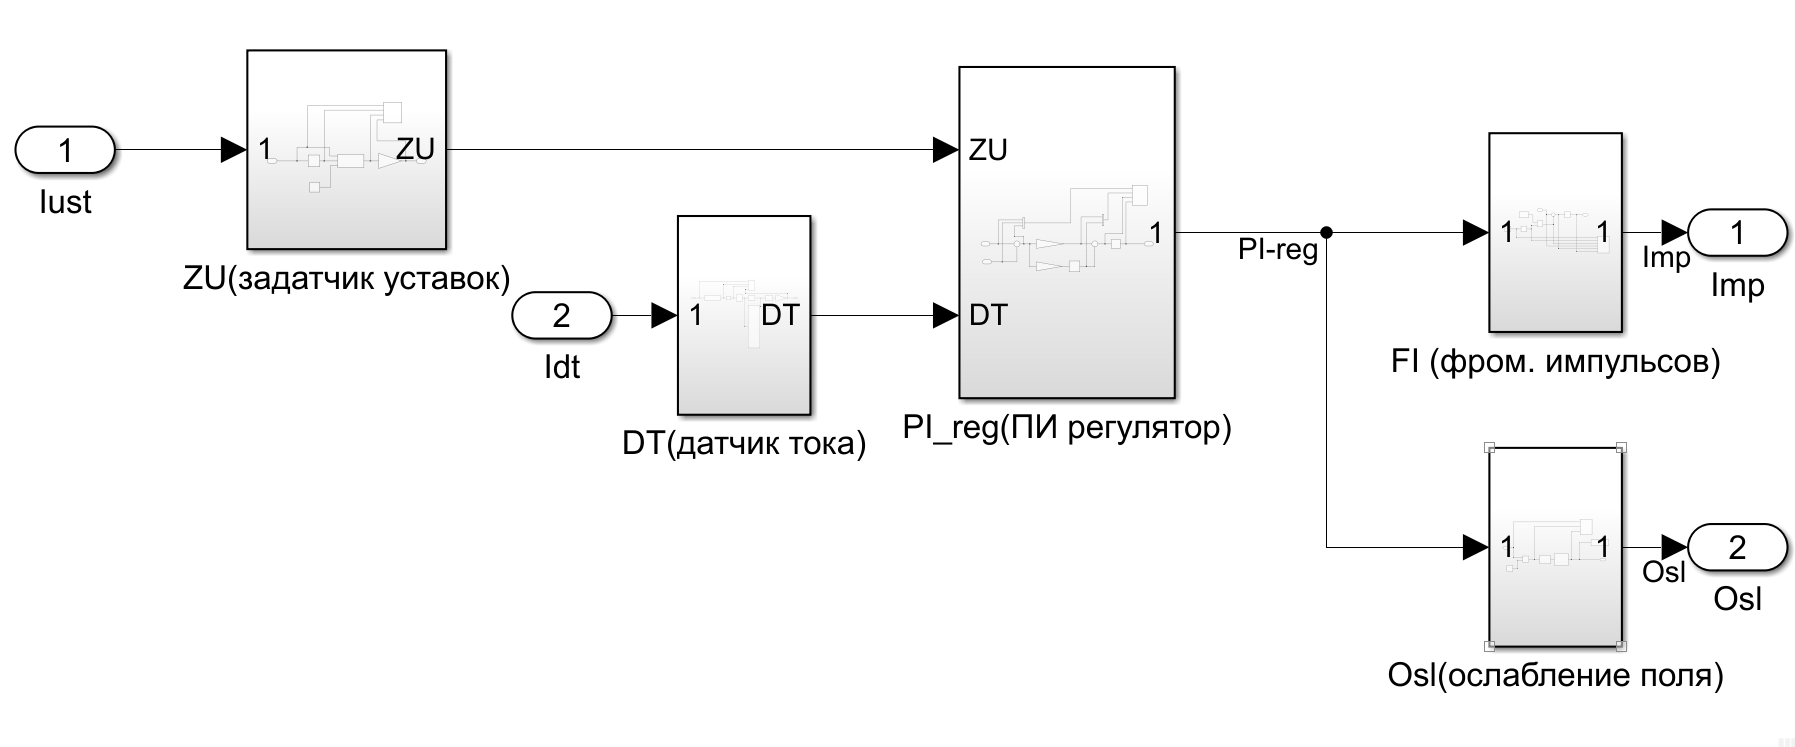

Рисунок 1. Компьютерная модель системы автоматического управления (САУ) в Simulink

Модель САУ (рисунок 1) состоит из блоков: задатчика уставок «ZU», датчика тока с цифровой обработкой сигнала «DT», регулятора тока «PI-reg»,  формирователя импульсов «FI» и управления возбуждением «Osl».

Для получения диаграмм сигналов на выходе САУ (выходных сигналов датчика/задатчика, регулятора,  формирователя импульсов и ОВ) произведем построение и расчет параметров компьютерных моделей блоков САУ (п.1.1.1 - 1.1.5).

**Параметры для снятия диаграмм тестовых сигналов блоков САУ:**

- ток ТЭД в расчетном режиме (ток уставки) Iя = Iуст, А.:

I_ust = 250;

- частота работы преобразователя fпр, Гц:

source.f_c = 700;

#### **1.1.1. Модель датчика тока:**

#### **1.1.1.1. Построение компьютерной модели и расчет параметров ДТ:**

В САУ ЭПС применены датчики тока «LEM». Выходные цепи датчиков  тока снабжены сглаживающими фильтрами для защиты МПСУ от импульсных  помех. Поэтому изменение выходных сигналов датчиков тока характеризуются дифференциальным уравнением апериодического звена 1-го порядка с постоянной времени Tдт выходного сглаживающего фильтра и коэффициентом усиления Kдт.

Компьютерная модель датчика тока и блока цифровой обработки сигнала в Simulink приведена на рисунке 2.

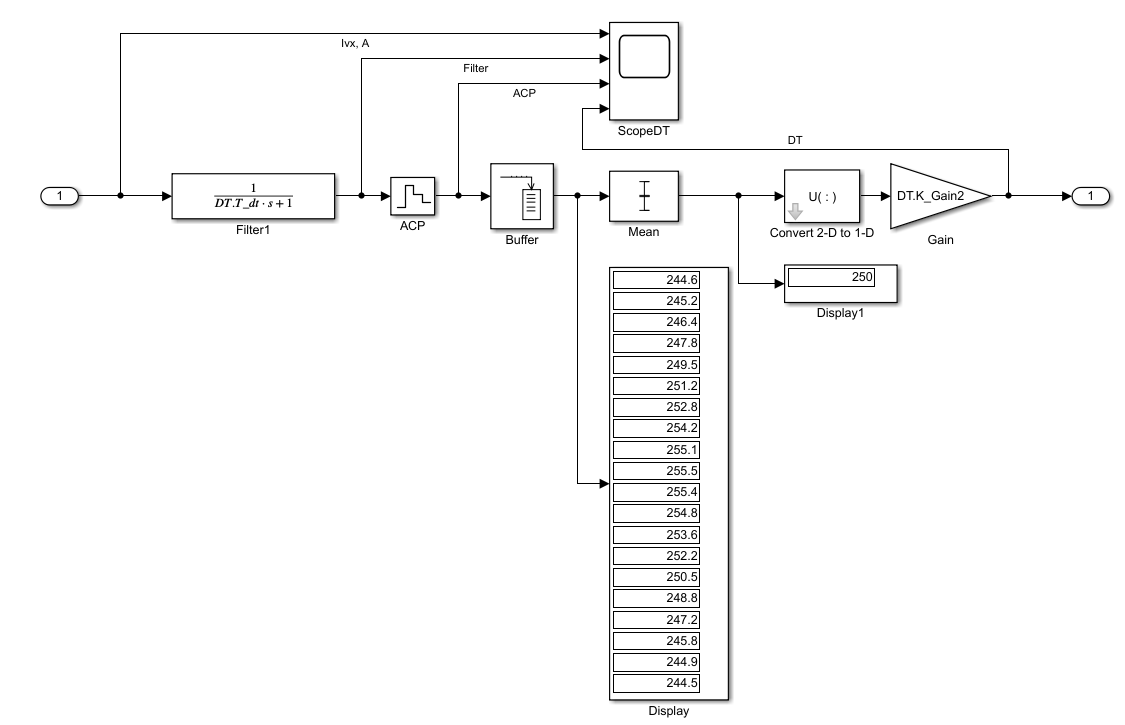

Рисунок 2. Компьютерная модель датчика тока и блока цифровой обработки сигнала в Simulink

Формирование выходных сигналов компьютерной модели датчика тока производится модулем «Filter1» (Transfer Fcn) посредством умножения сигнала тока ТЭД ia, подаваемого на вход «In 1», на передаточную функцию апериодического звена 1-го порядка с постоянной времени Tдт выходного сглаживающего фильтра, коэффициентом усиления датчика тока Kдт и масштабным множителем mдт:

Выбор коэффициента усиления датчика тока Kдт=Uдт/Iя, блок «Gain1» и масштабного коэффициента цифровой обработки сигналов датчиков тока mдт в производим так, чтобы Kдт*mдт=0,025, т.е. цифровой сигнал датчика тока должен быть в 40 раз меньше действительной величины тока ТЭД. Величину постоянной времени датчика тока блока «Filter1» Tдт принимаем равной 0.001 с.:

DT.T_dt = 0.001;

Блок компьютерной модели датчика тока производит цифровую обработку сигналов датчика тока, аналогично производимой в МПСУ, для формирования среднего за период управления значения. Цифровая обработка сигналов производится посредством 20-кратного квантования сигналов модуля  «Filter1» модулем «АСР» (Zero-Oder Hold) каждый ν-й период управления, равный  1/fпр с и суммирования квантованных сигналов модулем «Buffer».

Период квантования модуля «АСР» принимаем по формуле, с.:

где fпр - частота работы ШИП.

DT.T_kv1 = 1/(20*source.f_c);

Размер буфера модуля «Buffer» принимается равным 20 точек.

DT.Buffer_size = 20;

Все значения, полученные на каждый период управления, формируются в вектор размерностью I {1*20}, после чего вычисляется среднее значение элементов вектора посредством модуля «Mean».

Модуль«Convert 2D-1D» преобразует векторную величину модуля «Mean» в одномерный цифровой сигнал:

Коэффициент усиления блока «Gain1» принимаем по формуле:

DT.K_Gain2 = 0.025;

Далее полученные значения среднего за период управления сигнала датчика тока ТЭД  Iдт*v* передаются в регулятор РТЯ. 

#### **1.1.1.2. Диаграммы тестовых сигналов ДТ:**

На рисунке 3 приведена компьютерная модель тестирования блока датчика тока в Simulink при задании тока уставки Iуст:

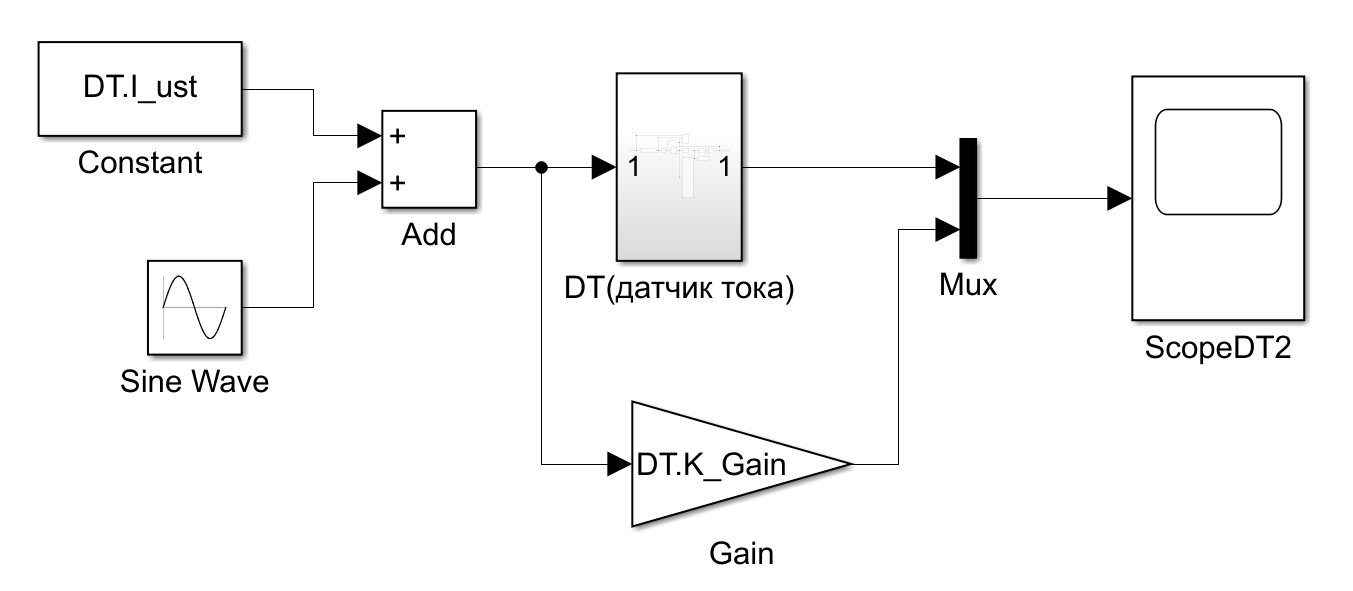

Рисунок 3. Компьютерная модель тестирования блока датчика тока в Simulink

При снятии осциллограмм сигналов датчика тока на вход блока подаем:

- Ток двиателя в расчетном режиме Iуст, А. в виде синусоидальной волны:

В окне параметров блока "Constant" вводим значение тока Iуст:

DT.I_ust = I_ust;

В окне параметров блока Sine Wave (Генератора непрерывной или дискретной синусоидальной волны) вводим значения амплитуды тока Iуст и угловой частоты модулирующего напряжения  w=2*π*fпр (рад/c). 

DT.Sine_Wave.amplitude = I_ust*0.1; %амплитуда тока Iуст
DT.Sine_Wave.freq = 2*pi*source.f_c; % угловая частота тока Iуст, рад/c.

- Коэффициент усиления датчика тока с масштабным множителем:

В окне параметров блока "Gain" вводим значение коэффициента усиления датчика тока с масштабным множителем, принимаемым:

DT.K_Gain = DT.K_Gain2;

Сигналы датчика тока:

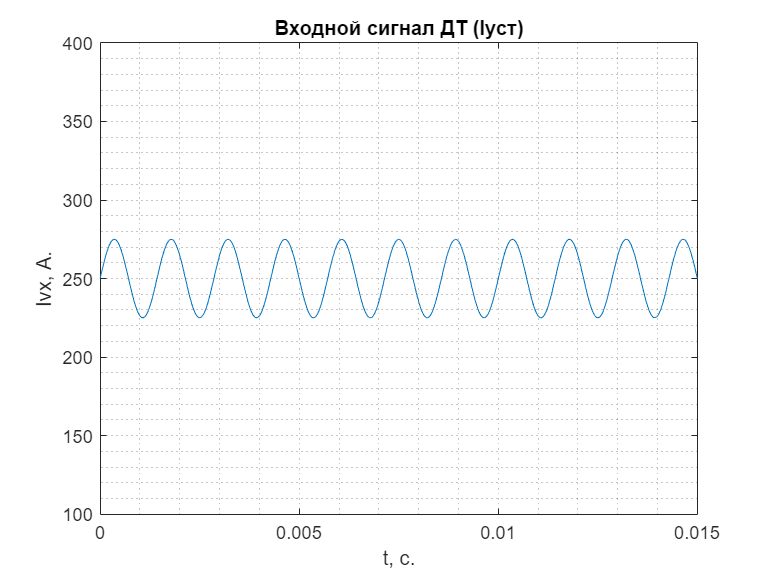

sim ('Block_DT.slx');
plot(ans.ScopeDT{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ivx, А.');
    title('Входной сигнал ДТ (Iуст)');
    xlim([0 0.015]);
    ylim([100 400]);

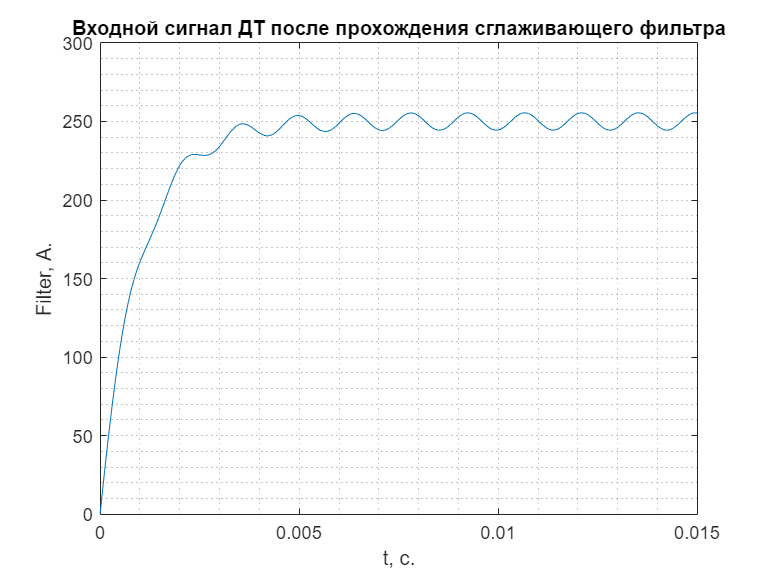

plot(ans.ScopeDT{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Filter, А.');
    title('Входной сигнал ДТ после прохождения сглаживающего фильтра');
    xlim([0 0.015]);

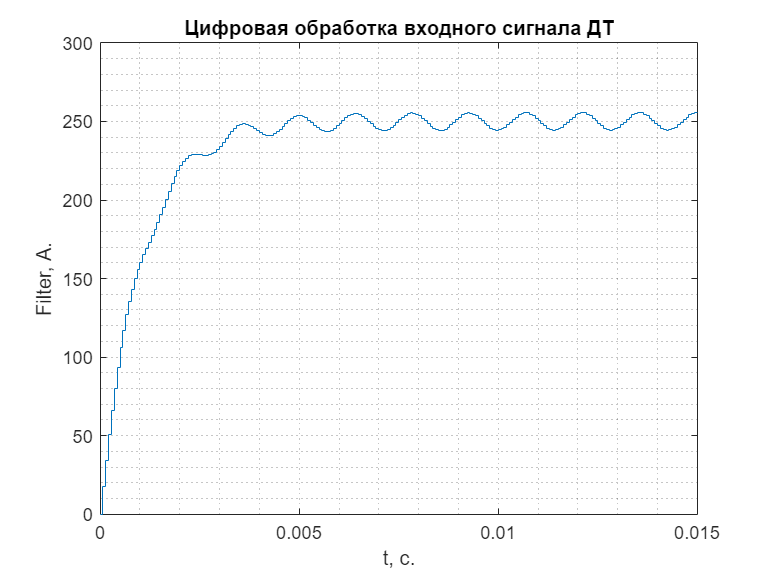

plot(ans.ScopeDT{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Filter, А.');
    title('Цифровая обработка входного сигнала ДТ');
    xlim([0 0.015]);

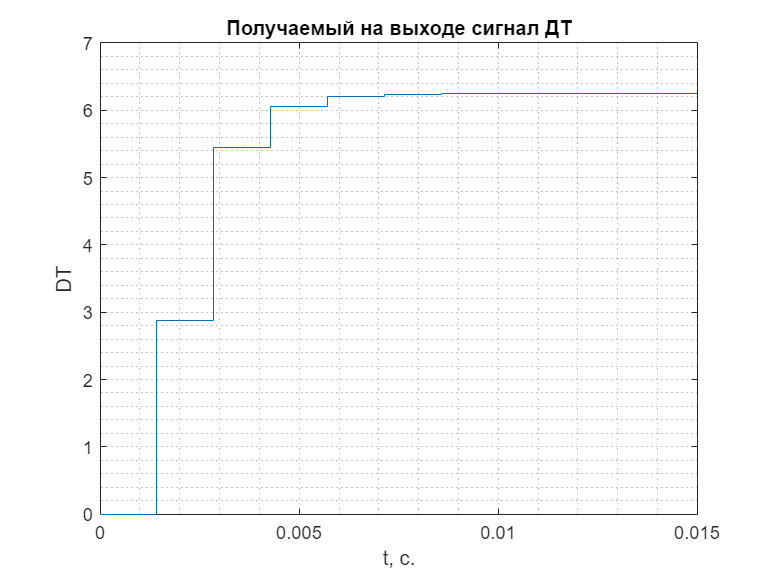

plot(ans.ScopeDT{4}.Values);
    grid("minor")
    xlabel('t, с.');
    title('Получаемый на выходе сигнал ДТ');
    xlim([0 0.015]);

Выходной и входной сигналы датчика тока:

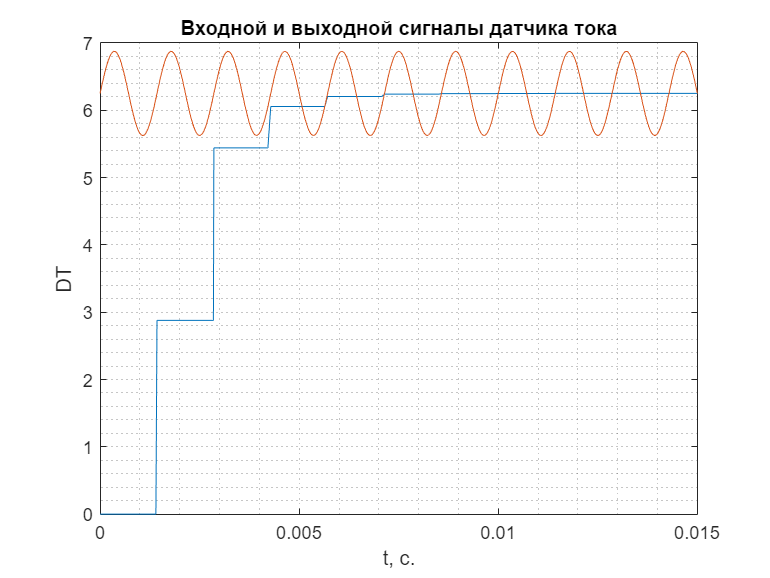

plot(ans.ScopeDT2{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('DT');
    title('Входной и выходной сигналы датчика тока');
    xlim([0 0.015]);

#### **1.1.2. Модель задатчика уставок:**

#### **1.1.2.1. Построение компьютерной модели ЗУ:**

Компьютерная модель задатчика уставок в Simulink приведена на рисунке 4.

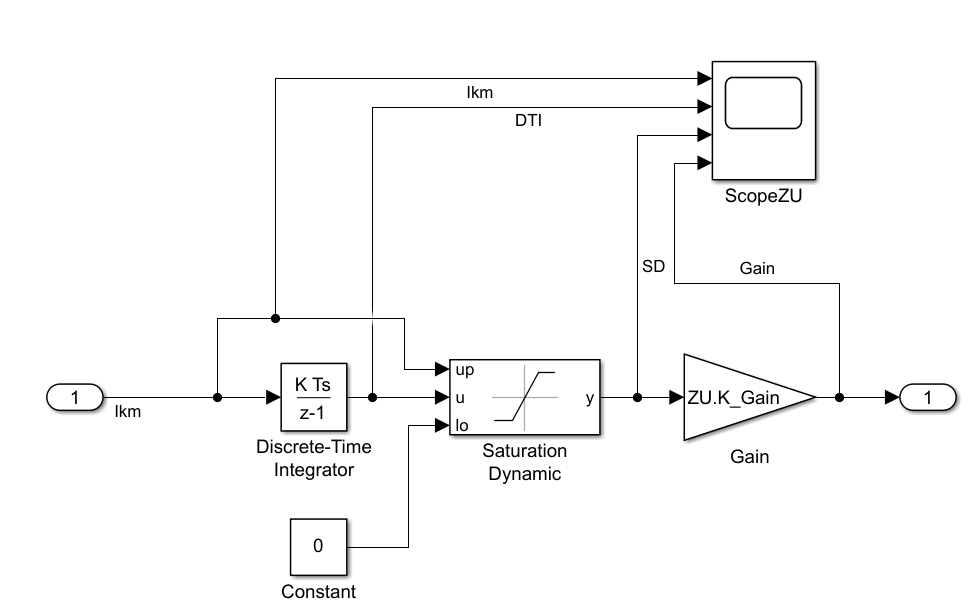

Рисунок 4. Компьютерная модель задатчика уставок в Simulink

Модуль задатчик уставок обеспечивает плавное нарастание уставки тока  ТЭД на интервале 1,5…2 с. 

Задатчик уставок из блоков:

- «Gain» - масштабирует сигнал задатчика уставок; 

- «DTI» - осуществляет интегрирование входного сигнала; 

- «Saturation Dynamic» -  осуществляет динамическое ограничение входного сигнала задатчика уставок уровнем уставки тока якоря;

- «Constant1» - задает нижний уровень ограничения;

- «In1, Out1» - вход и выход блока;

- «Scope» - осциллограф.

Коэффициент усиления блока «Gain» вычисляется, с учетом коэффициента датчика тока, по формуле:

где [Kдт∙mдт] - коэффициент усиления задатчика уставок с масштабным множителем.

ZU.K_Gain = 0.025;

#### **1.1.2.2. Диаграммы тестовых сигналов ЗУ:**

На рисунке 5 приведена компьютерная модель тестирования блока задатчика уставок в Simulink при задании тока уставки Iуст:

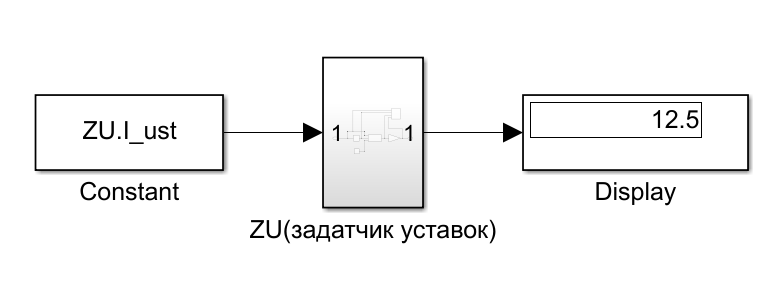

Рисунок 5. Компьютерная модель тестирования блока задатчика уставок в Simulink

Уровнень уставки тока якоря:

При снятии осциллограмм сигналов задатчика уставок на вход блока подаем удвоенный ток двиателя в расчетном режиме Iуст, А.:

ZU.I_ust = I_ust*2;

Сигналы задатчика уставок:

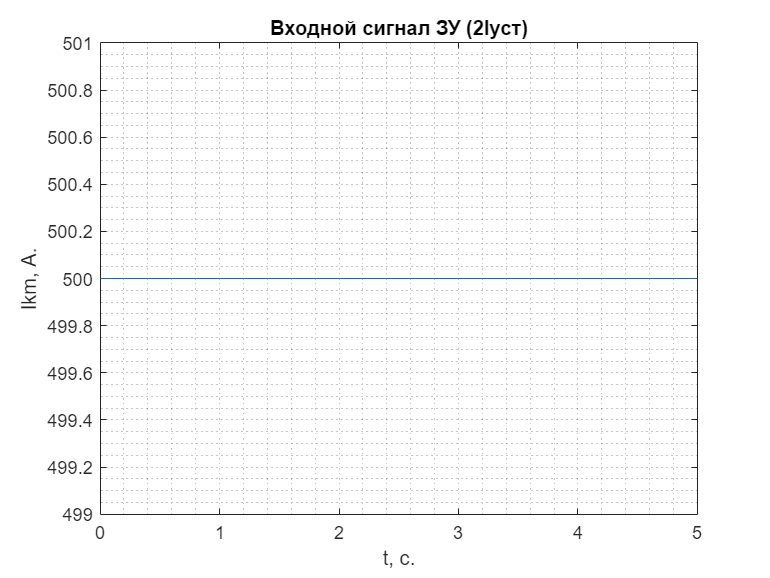

sim ('Block_ZU.slx');
plot(ans.ScopeZU{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ikm, А.');
    title('Входной сигнал ЗУ (2Iуст)');

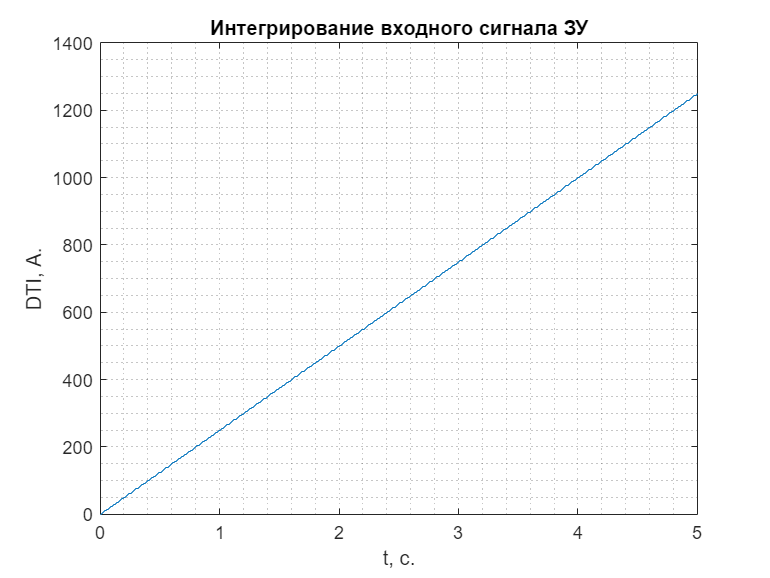

plot(ans.ScopeZU{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('DTI, А.');
    title('Интегрирование входного сигнала ЗУ');

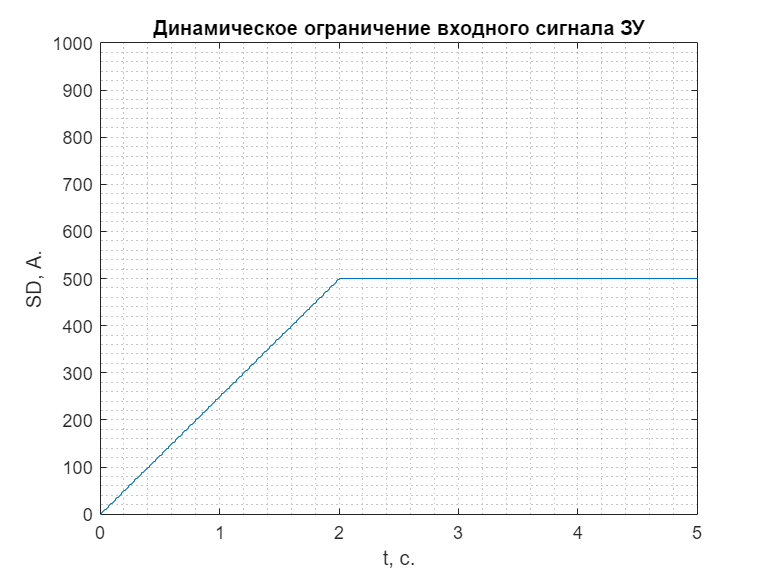

plot(ans.ScopeZU{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('SD, А.');
    title('Динамическое ограничение входного сигнала ЗУ');
    ylim([0 1000]);

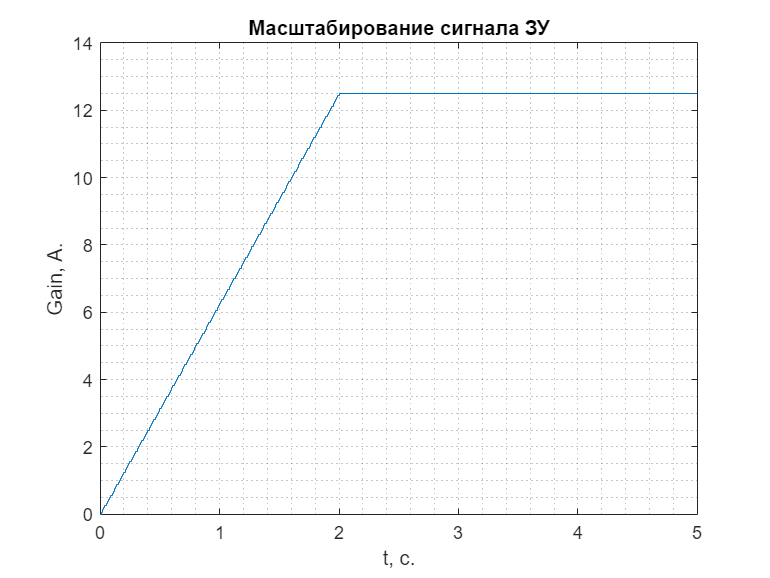

plot(ans.ScopeZU{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Gain, А.');
    title('Масштабирование сигнала ЗУ');

Сигналы задатчика уставок в увеличенном масштабе:

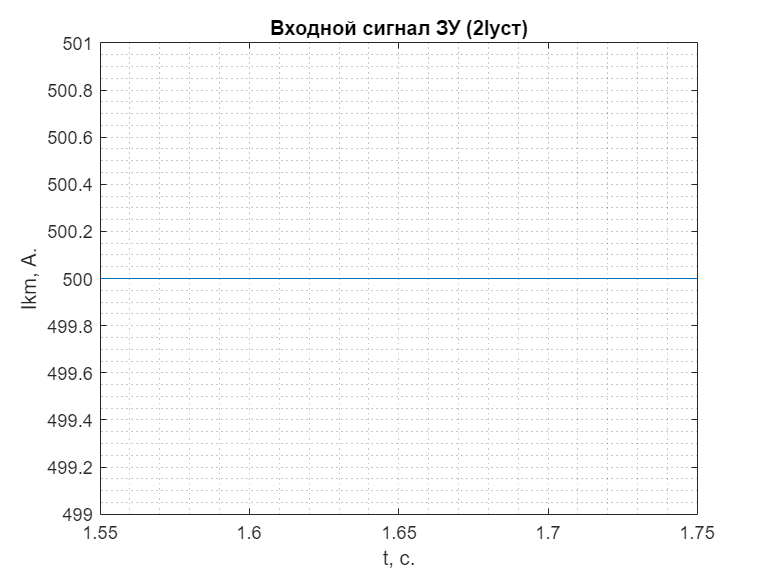

plot(ans.ScopeZU{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ikm, А.');
    title('Входной сигнал ЗУ (2Iуст)');
    xlim([1.55 1.75]);

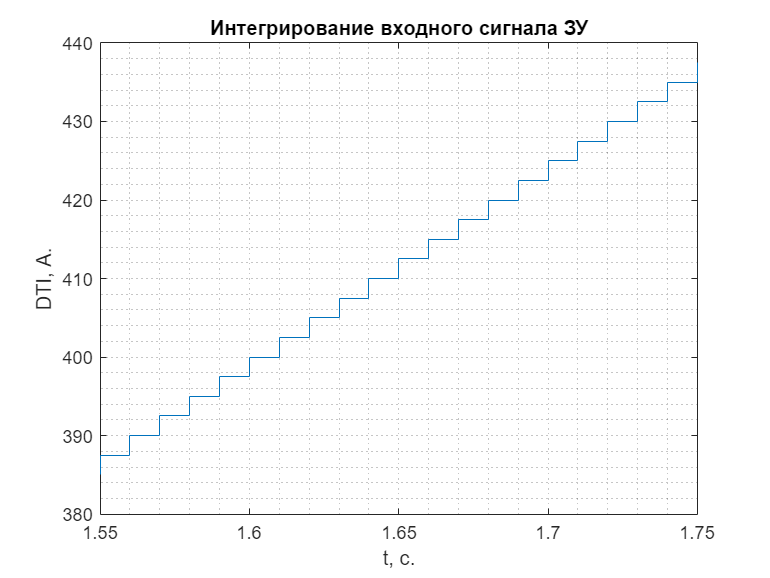

plot(ans.ScopeZU{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('DTI, А.');
    title('Интегрирование входного сигнала ЗУ');
    xlim([1.55 1.75]);

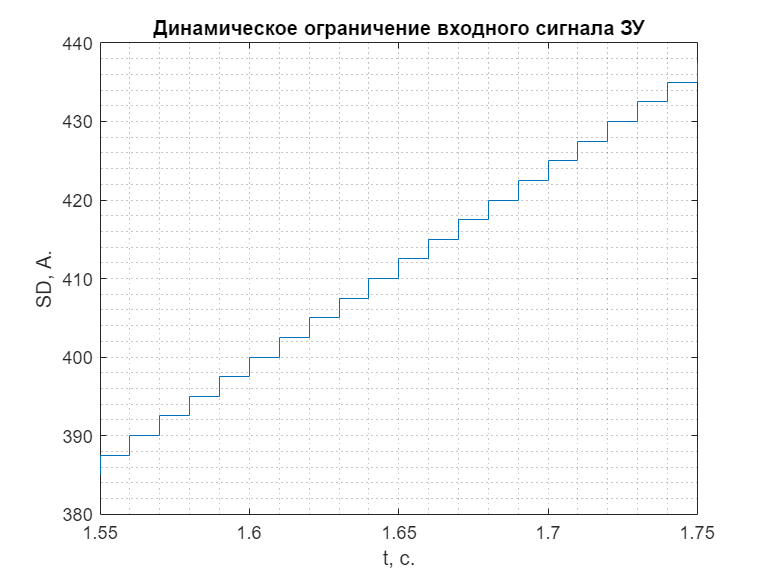

plot(ans.ScopeZU{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('SD, А.');
    title('Динамическое ограничение входного сигнала ЗУ');
    xlim([1.55 1.75]);

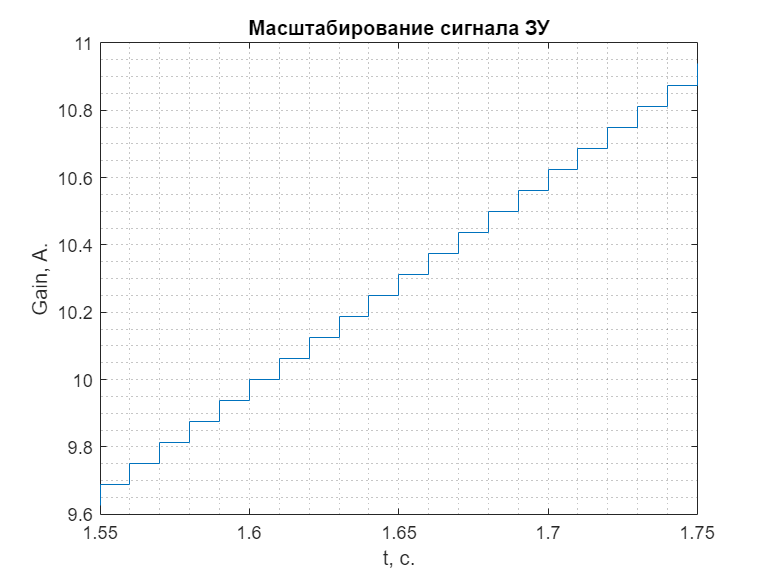

plot(ans.ScopeZU{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Gain, А.');
    title('Масштабирование сигнала ЗУ');
    xlim([1.55 1.75]);

#### **1.1.3. Модель ПИ-регулятора:**

#### **1.1.3.1. Построение компьютерной модели ПИ-регулятора:**

Компьютерная модель ПИ-регулятора тока РТЯ в Simulink приведена на рисунке 6.

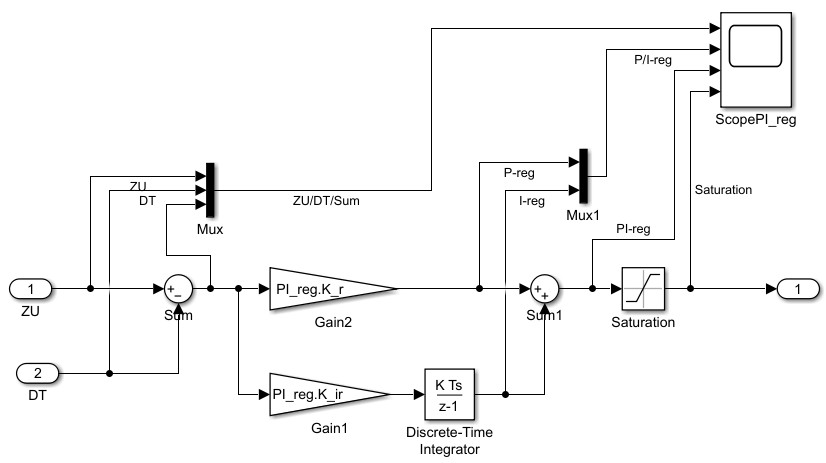

Рисунок 6. Компьютерная модель ПИ-регулятора тока РТЯ в Simulink

Дискретное уравнение вычисления выходного сиг нала блок-программы регулятора МПСУ с пропорционально-интегральным  законом регулирования для (v+1) периода управления в компьютерной модели воспроизводится модулями пропорциональной и интегральной обработки сигнала рассогласования (mзу∙Iуст-I дтv).

На схеме рисунка 6 сумматор «Sum1» вычисляет сигнал рассогласования (mзу∙Iуст-I дтv). На вход «In2» подается средний за v-й период управления сигнал датчика тока якоря I дтv. Сумматор «Sum 2» производит суммирование  сигналов пропорционального и интегрального каналов регулятора. Коэффициент усиления пропорционального канала регулятора Kр задается модулем «Gain 2», коэффициент усиления интегрального Kир канала задается модулем «Gain 1».

Параметры настройки - коэффициенты усиления пропорционального Kр и интегрального Kир каналов ПИ-регулятора связаны с постоянной времени интегратора Tир и шагом интегрирования ∆t, равным периоду управления (∆t=τу), следующим соотношением, 1/А:

Выбор постоянных времени и коэффициентов усиления регуляторов производят посредством моделирования переходных процессов на компьютерной модели методом незатухающих колебаний или методом CHR.

Параметры регулятора задаем предварительно: 

- коэфициент усиления пропорционального канала регулятора Kр принимаем равным 0,5:

PI_reg.K_r = 0.5;    

- коэфициент усиления интегрального канала регулятора Kир принимаем равным 1:

PI_reg.K_ir = 1;  

В блоке интегратора задаем время выборки "Sample time" равным 1/fпр:

PI_reg.DTI_st = 1/source.f_c;

В блоке насыщения "Saturation" задаем ограничение выходного сигнала на уровнях от 1 до 0:

PI_reg.StUp_limit = 1;
PI_reg.StLow_limit = 0;

#### **1.1.3.2. Диаграммы тестовых сигналов ПИ-регулятора:**

На рисунке 7 приведена компьютерная модель тестирования блока ПИ-регулятора в Simulink при задании тока уставки Iуст:

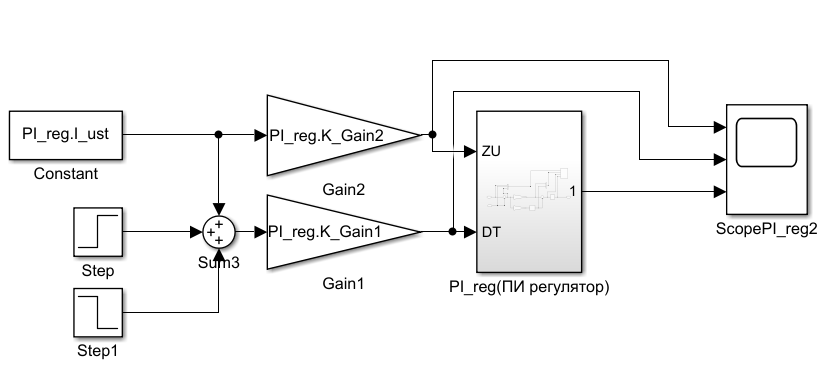

Рисунок 7. Компьютерная модель тестирования блока ПИ-регулятора в Simulink

При снятии осциллограмм сигналов ПИ-регулятора на вход блока подаем:

- Ток двиателя в расчетном режиме Iуст, А.:

В окне параметров блока "Constant" вводим значение тока Iуст:

PI_reg.I_ust = I_ust;

- Коэффициенты усиления датчика тока и задатчика уставок с масштабным множителем:

В окне параметров блока "Gain1" вводим значение коэффициента усиления датчика тока с масштабным множителем, принимаемым:

PI_reg.K_Gain1 = DT.K_Gain2;

В окне параметров блока "Gain2" вводим значение коэффициента усиления задатчика уставок с масштабным множителем, принимаемым:

PI_reg.K_Gain2 = ZU.K_Gain;

В окне параметров блоков Step  и Step1 вводим значение времени шага и выходного значения после шага:

PI_reg.Step_time = 3;
PI_reg.Step_FinalValue = 40;
PI_reg.Step1_time = 1;
PI_reg.Step1_FinalValue = -20;

Сигналы регулятора:

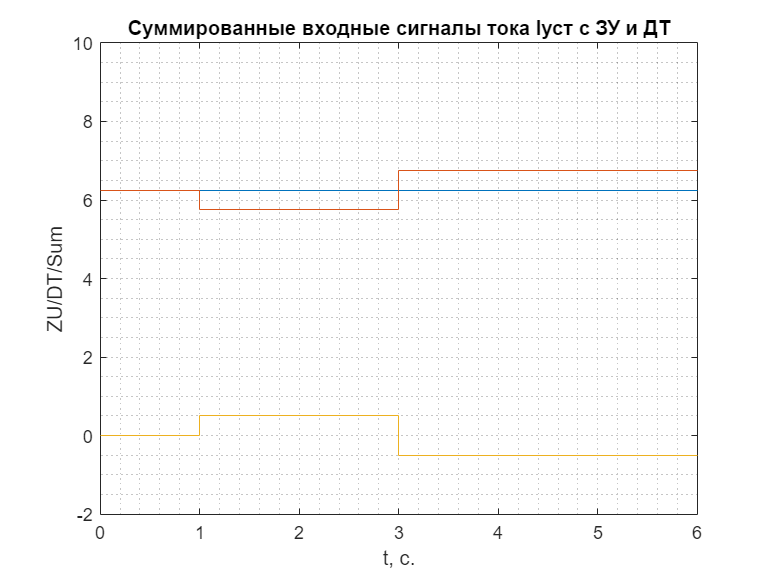

sim ('Block_PI_regulator.slx');
plot(ans.ScopePI_reg{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('ZU/DT/Sum');
    title('Суммированные входные сигналы тока Iуст с ЗУ и ДТ');
     ylim([-2 10]);

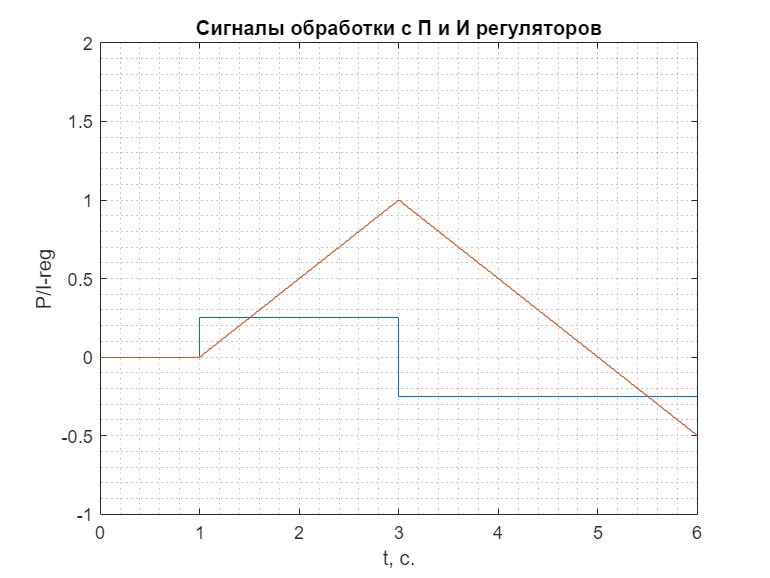

    sim ('Block_PI_regulator.slx');
plot(ans.ScopePI_reg{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('P/I-reg');
    title('Сигналы обработки с П и И регуляторов');
     ylim([-1 2]);

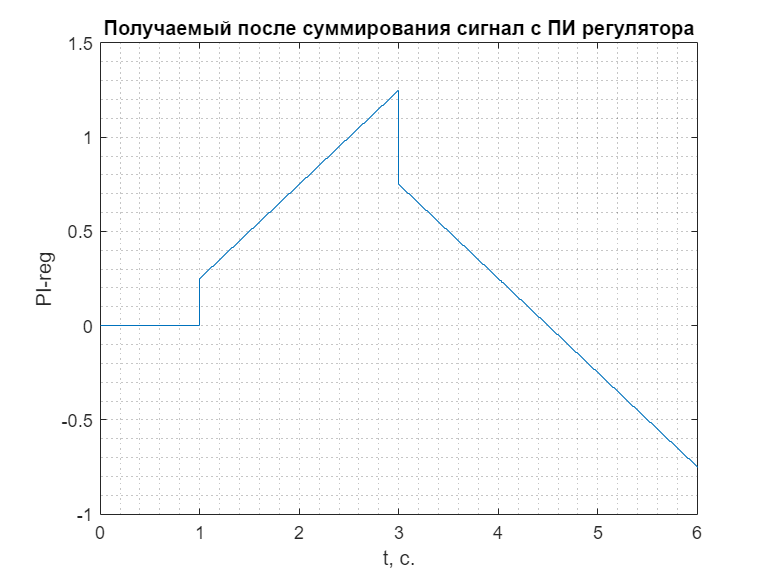

plot(ans.ScopePI_reg{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Получаемый после суммирования сигнал с ПИ регулятора');

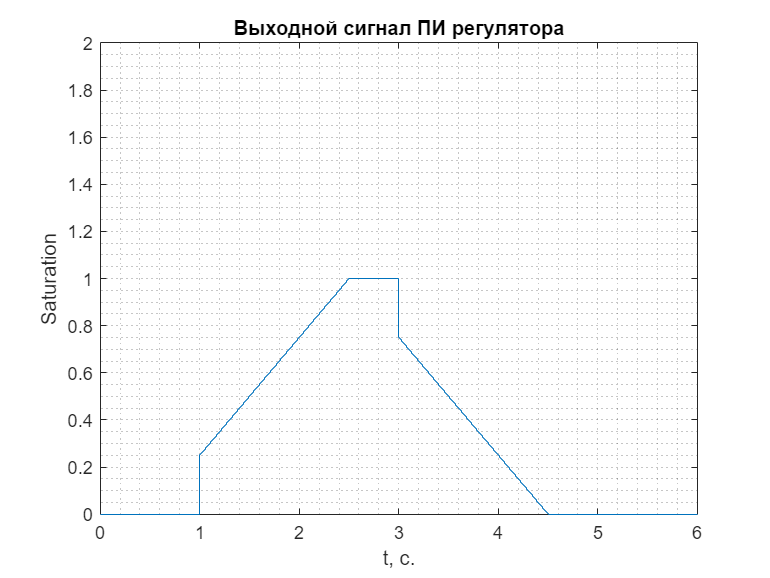

plot(ans.ScopePI_reg{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Saturation');
    title('Выходной сигнал ПИ регулятора');
     ylim([0 2]);

Входные и выходные сигналы регулятора:

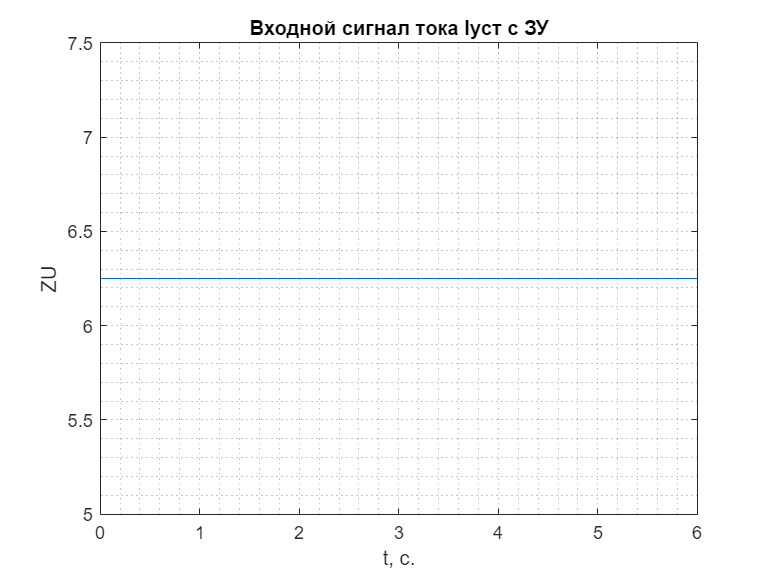

plot(ans.ScopePI_reg2{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('ZU');
    title('Входной сигнал тока Iуст с ЗУ');

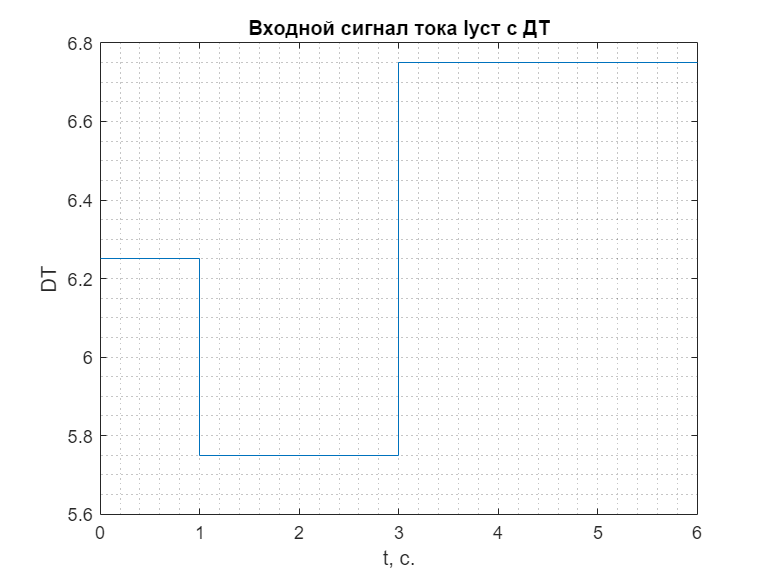

plot(ans.ScopePI_reg2{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('DT');
    title('Входной сигнал тока Iуст с ДТ');

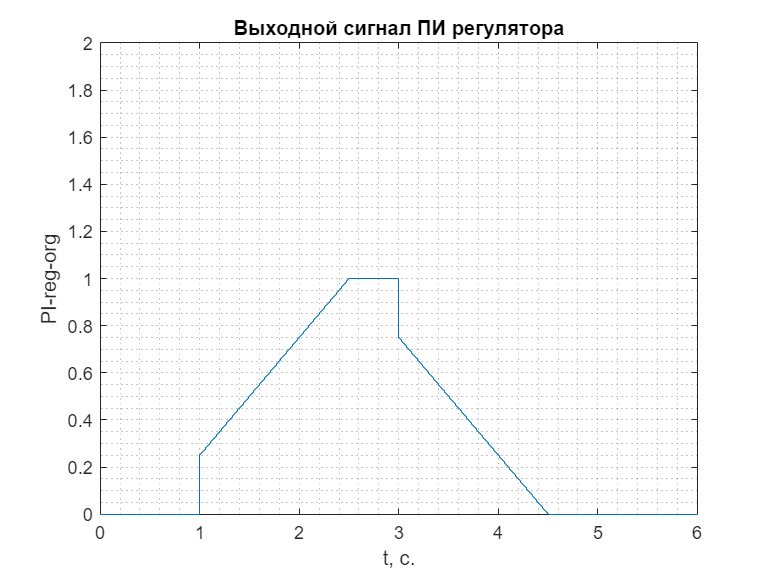

plot(ans.ScopePI_reg2{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg-org');
    title('Выходной сигнал ПИ регулятора');
    ylim([0 2]);

#### **1.1.4. Модель формирователя импульсов:**

#### **1.1.4.1. Построение компьютерной модели формирователя импульсов:**

Компьютерная модель формирователя импульсов в Simulink приведена на рисунке 8.

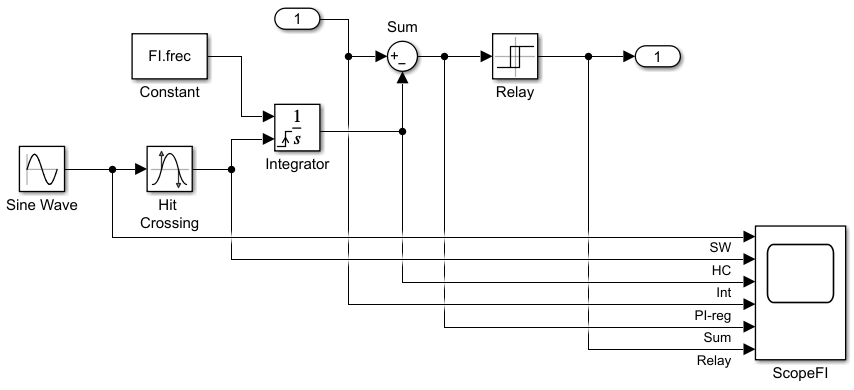

Рисунок 8. Компьютерная модель формирователя импульсов в Simulink

Выходная переменная Ср регулятора РТЯ передается в таймер, посредством которого формируется интервал времени tр, соответствующий коэффициенту заполнения γ.

Таймер производит отсчет интервалов времени работы управляемого ключевого элемента tр относительно импульсов синхронизации uси.

Формирователь импульсов состоит из блоков (рисунок 8):

«Integrator» - формирует пилообразное напряжение с периодом 1/f и амплитудой 1;

«Hit Crossing» - осуществляет сброс интегратора на каждом цикле работы САУ;

«Sine Wave» - задает синусоидальный сигнал синхронизации с частотой πf ;

«Constant1» - задает амплитуду пилообразного напряжения;

«Sum» - суммирует сигнал регулятора и сигнал пилообразного напряжения;

«Relay1» - формирует интервал времени работы управляемого ключевого элемента; 

«In1, Out1» - вход и выход блока;

«Scope» - осциллограф.

Параметры ввода компьютерной модели формирователя импульсов:

В окне параметров блока Sine Wave (Генератора непрерывной или дискретной синусоидальной волны) вводим значение угловой частоты модулирующего напряжения  w=π*fпр (рад/c). 

FI.Sine_Wave.freq = pi*source.f_c; % угловая частота, рад/c.

В окне параметров блока "Constant" вводим значение частоты работы преобразователя fпр, Гц:

FI.frec = source.f_c;

#### **1.1.4.2. Диаграммы тестовых сигналов формирователя импульсов:**

На рисунке 9 приведена компьютерная модель тестирования блока формирователя импульсов в Simulink:

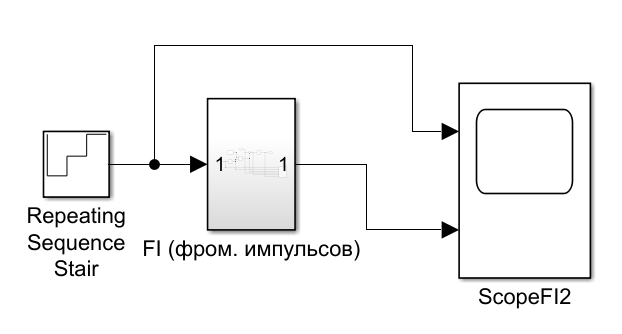

Рисунок 9. Компьютерная модель тестирования блока формирователя импульсов в Simulink

При снятии осциллограмм сигналов формирователя импульсов на вход блока подаем:

- значение коэффициента заполнения γ в виде массива:

В окне параметров блока "Repeating Sequence Stair" (Повторяющаяся последовательность (ступенька)) вводим значения коэффициента заполнения и задаем время выборки "Sample time" равным 0,01 с.:

FI.RSS_Vector = [0.1 0.5 0.99];
FI.RSS_st = 0.01;

Сигналы формирователя импульсов:

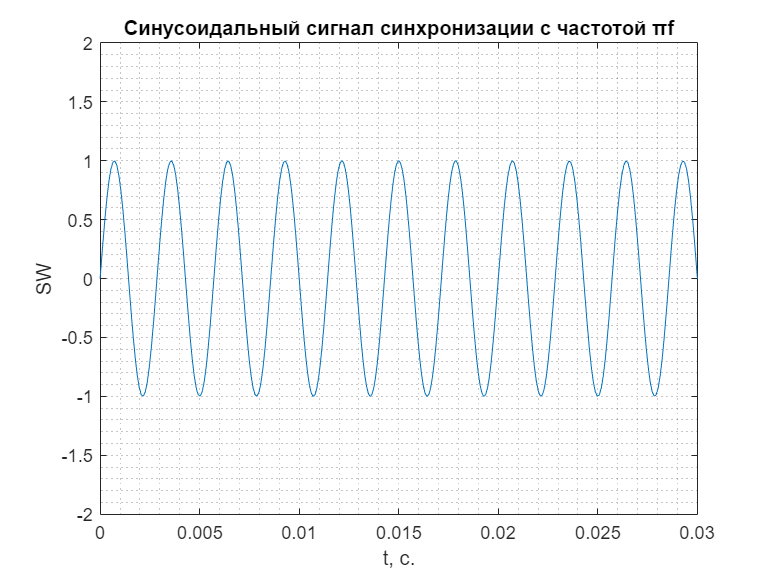

sim ('Block_FI.slx');
plot(ans.ScopeFI{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('SW');
    title('Синусоидальный сигнал синхронизации с частотой πf');
    ylim([-2 2]);

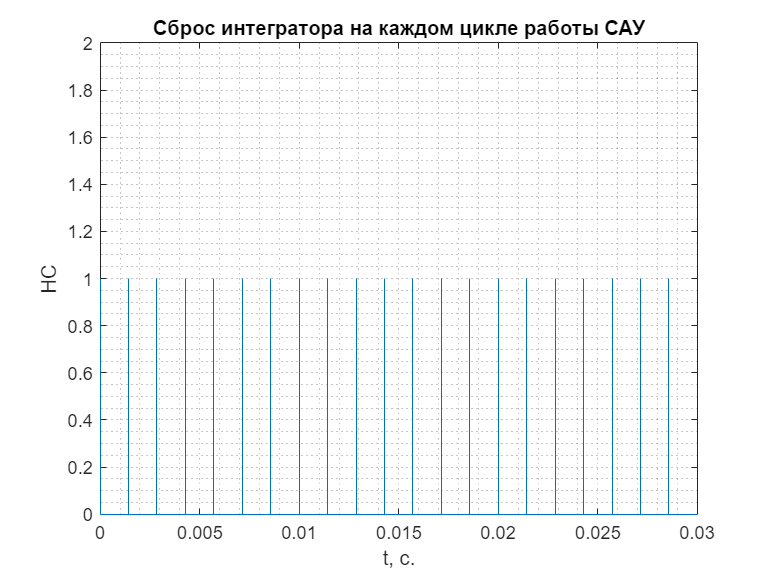

plot(ans.ScopeFI{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('HC');
    title('Сброс интегратора на каждом цикле работы САУ');
    ylim([0 2]);

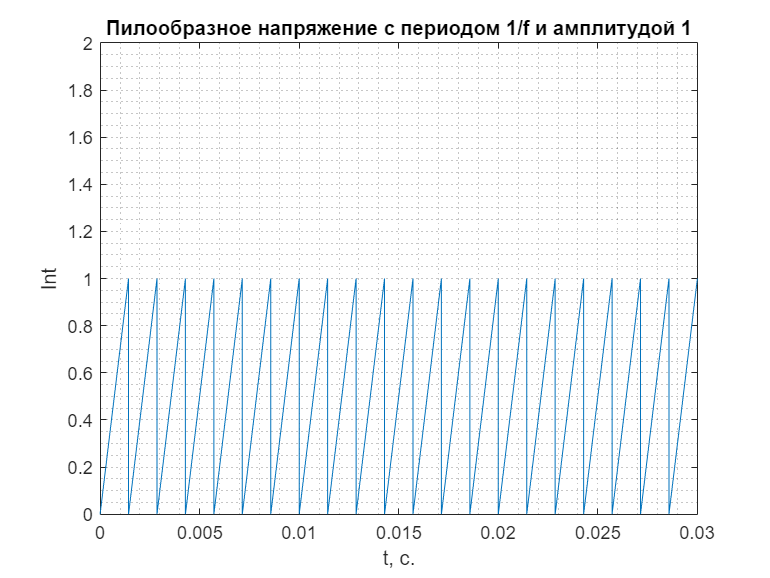

plot(ans.ScopeFI{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Int');
    title('Пилообразное напряжение с периодом 1/f и амплитудой 1');
    ylim([0 2]);

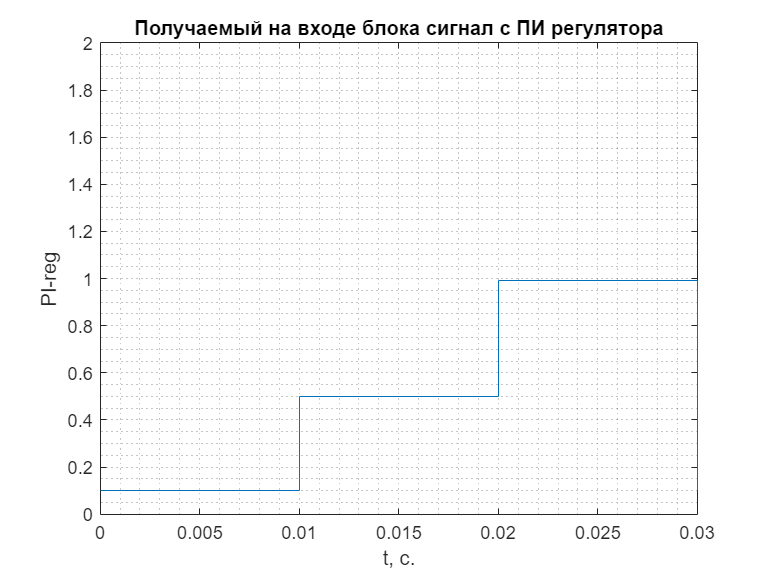

plot(ans.ScopeFI{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Получаемый на входе блока сигнал с ПИ регулятора');
    ylim([0 2]);

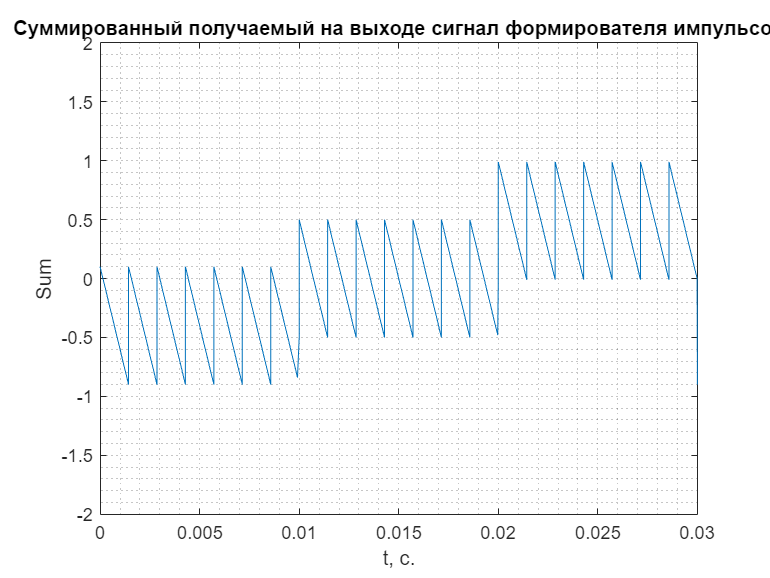

plot(ans.ScopeFI{5}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Sum');
    title('Суммированный получаемый на выходе сигнал формирователя импульсов');
    ylim([-2 2]);

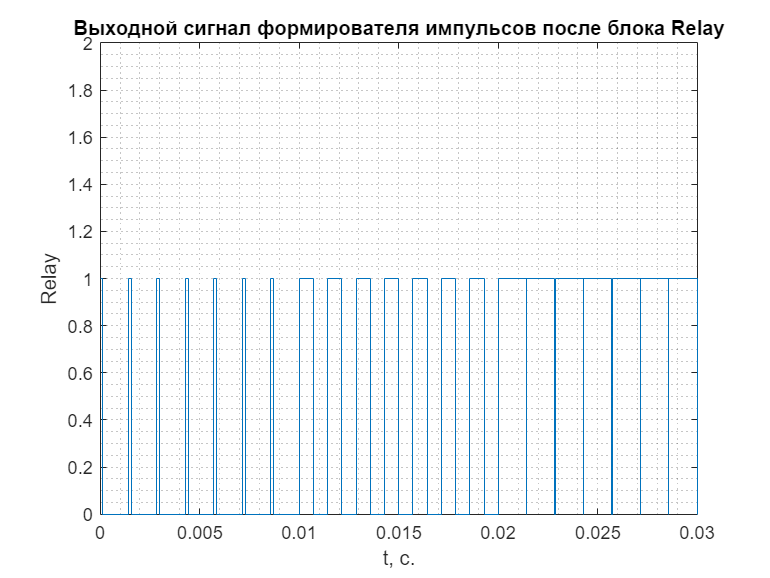

plot(ans.ScopeFI{6}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Relay');
    title('Выходной сигнал формирователя импульсов после блока Relay');
    ylim([0 2]);

Входной и выходной сигнал формирователя импульсов:

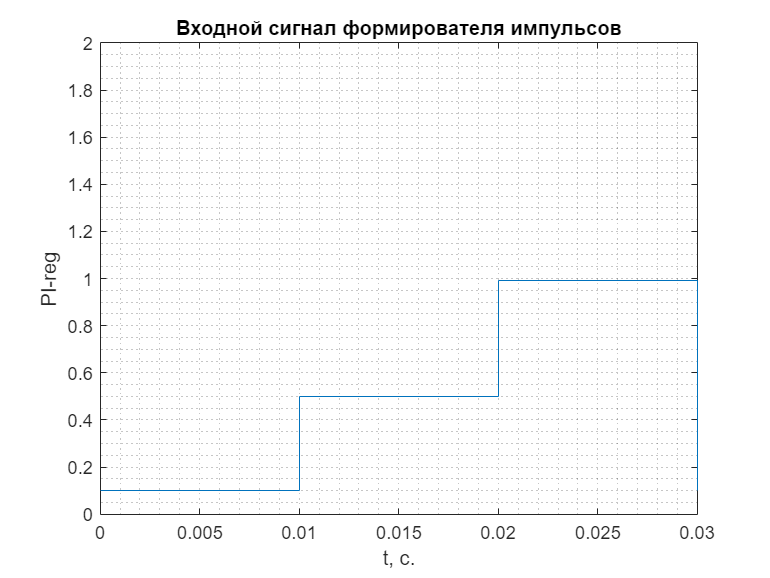

plot(ans.ScopeFI2{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Входной сигнал формирователя импульсов');
    ylim([0 2]);

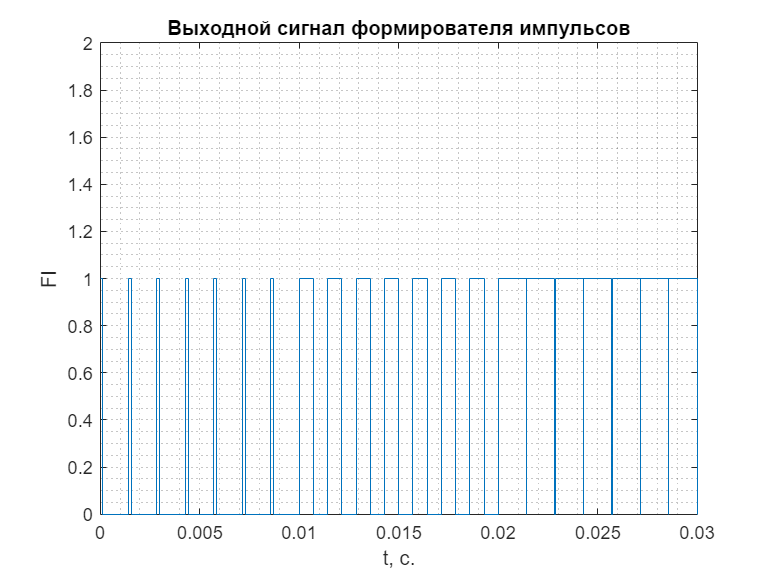

plot(ans.ScopeFI2{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('FI');
    title('Выходной сигнал формирователя импульсов');
    ylim([0 2]);

#### **1.1.5. Модель управления ослаблением поля:**

#### **1.1.5.1. Построение компьютерной модели управления ослаблением поля:**

Компьютерная модель управления ослаблением поля в Simulink приведена на рисунке 10.

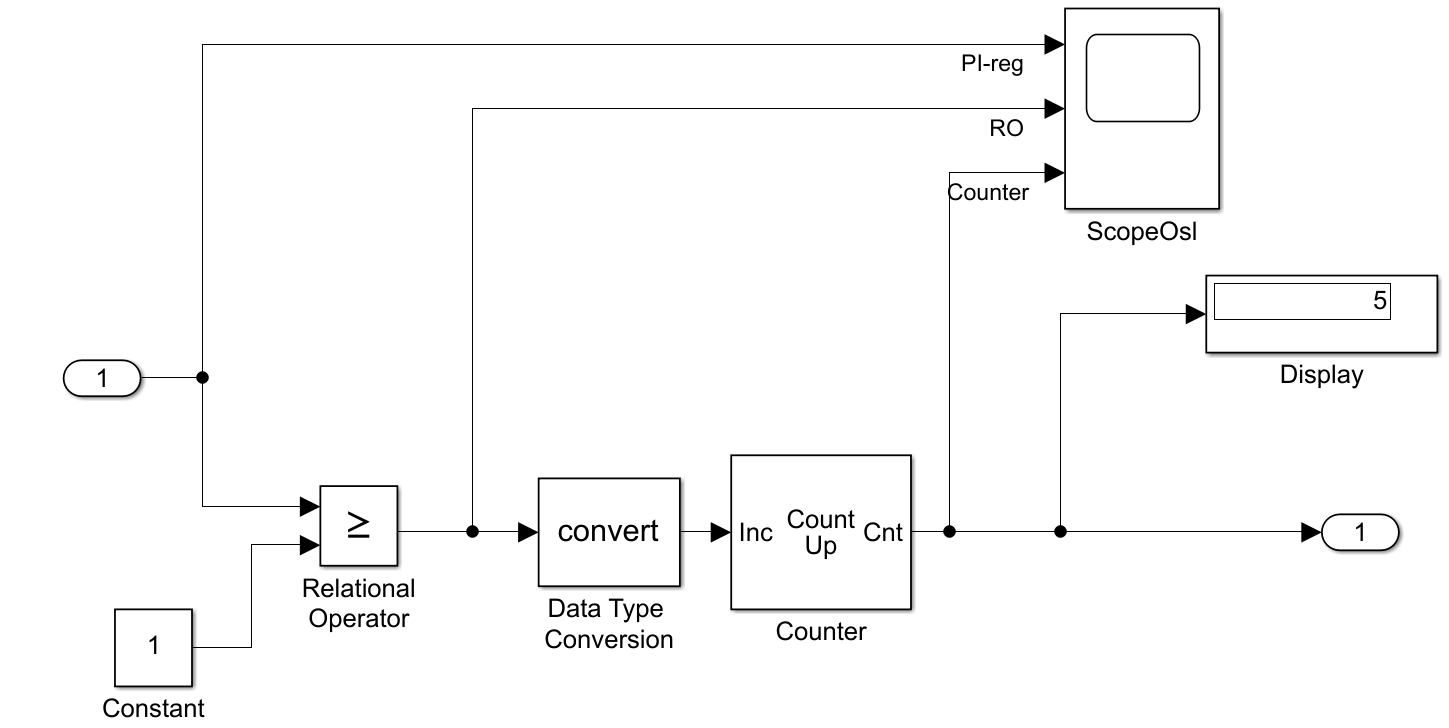

Рисунок 10. Компьютерная модель управления ослаблением поля в Simulink

Блок управления возбуждени ТЭД состоит из блоков (рисунок 10):

- «Costant1» - задает постоянный сигнал уровнем 1;

- «Relation Operator» - проверяет условие, при котором входной сигнал достигает единичного уровня, и формирует единичный сигнал в случае выполнения условия;

- «Data Type Conversion» - преобразует логический сигнал блока «Relation Operator» в сигнал типа Double;

- «Counter» - счетчик, производит подсчет количества единичных импульсов, приходящих на вход блока;

- «In1, Out1» - вход и выход блока;

- «Scope» - осциллограф;

- «Display» - отображает количество ступеней ослабления поля.

Параметры ввода компьютерной модели управления ослаблением поля:

В окне параметров блока "Counter" вводим максимальное количество подсчета единичных импульсов, приходящих на вход блока:

Osl.Counter_MaxCount = 10;

#### **1.1.5.2. Диаграммы тестовых сигналов блока управления ослаблением поля:**

На рисунке 11 приведена компьютерная модель тестирования блока управления ослаблением поля в Simulink:

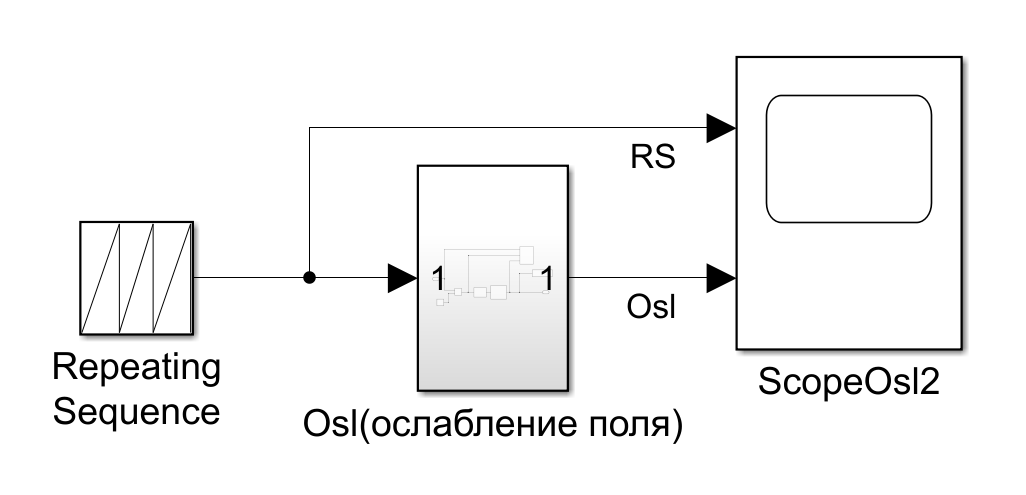

Рисунок 11. Компьютерная модель тестирования блока управления ослаблением поля в Simulink

При снятии осциллограмм сигналов управления ослаблением поля на вход блока подаем:

- Сигнал с ПИ регулятора в виде пилообразного напряжения блока "Repeating Sequence":

Параметры блока "Repeating Sequence" ГПН (генератор пилообразного напряжения):

В окне параметров ГПН задаем необходимые значения в виде массива данных:

Osl.RepSec.Time = [0 1]; % период пилообразного напряжения
Osl.RepSec.Output = [0 2]; % амплитуда пилообразного напряжения

Сигналы блока управления ослаблением поля:

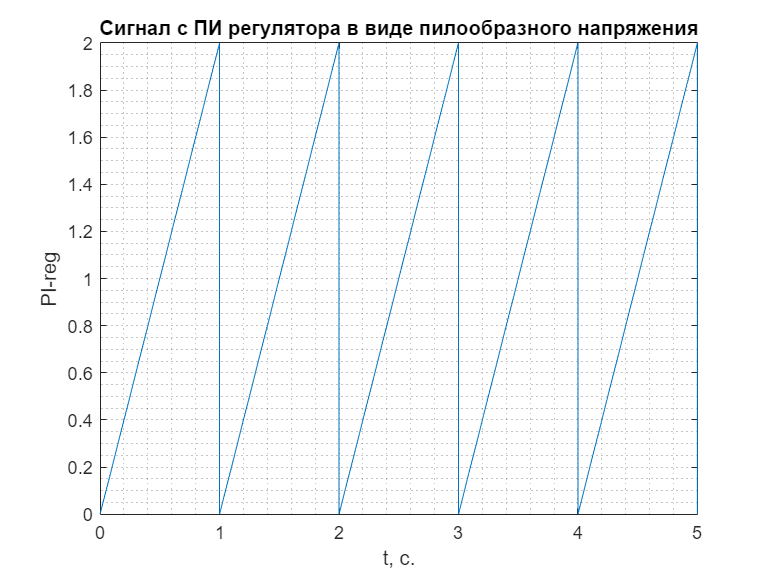

sim ('Block_Osl.slx');
plot(ans.ScopeOsl{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Сигнал с ПИ регулятора в виде пилообразного напряжения');

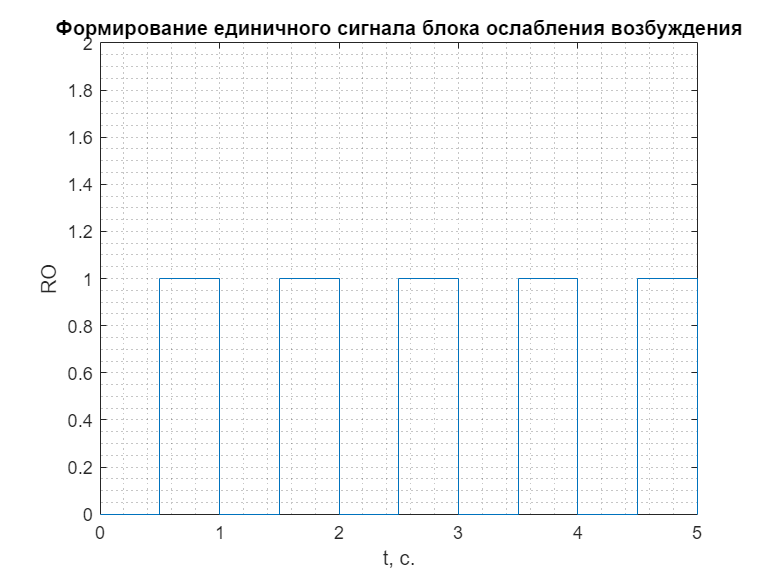

plot(ans.ScopeOsl{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('RO');
    title('Формирование единичного сигнала блока ослабления возбуждения'); 
    ylim([0 2]);

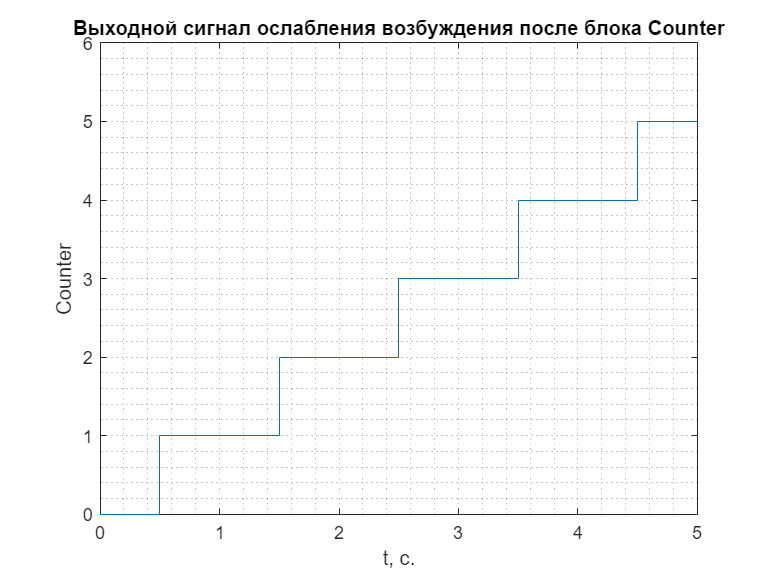

plot(ans.ScopeOsl{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Counter');
    title('Выходной сигнал ослабления возбуждения после блока Counter');
    ylim([0 6]);

Входной и выходной сигнал блока Ослабления возбуждения:

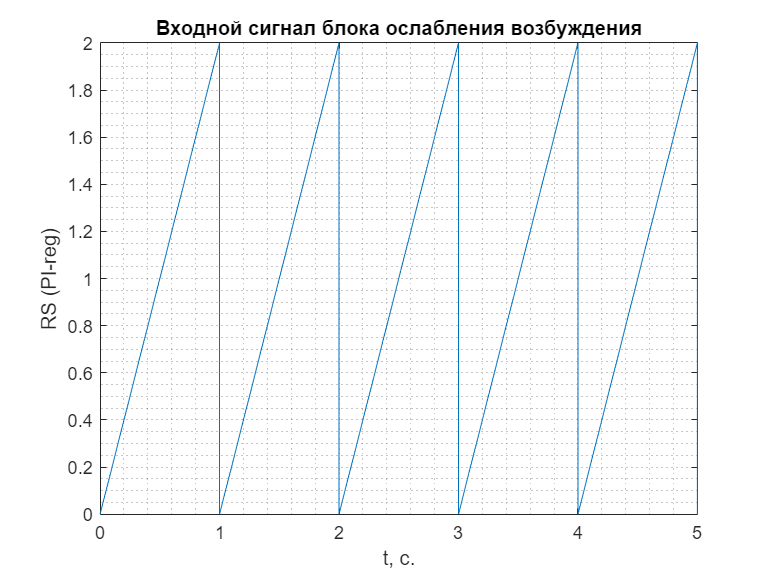

plot(ans.ScopeOsl2{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('RS (PI-reg)');
    title('Входной сигнал блока ослабления возбуждения');

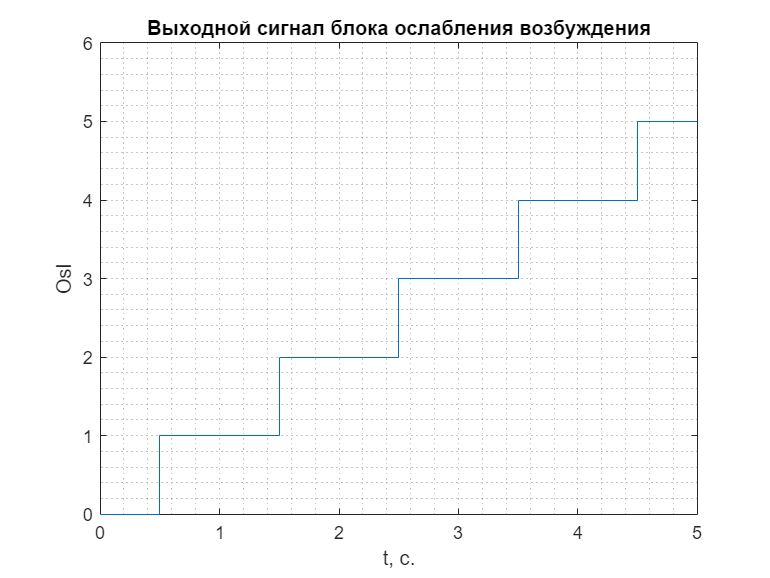

plot(ans.ScopeOsl2{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Osl');
    title('Выходной сигнал блока ослабления возбуждения');
    ylim([0 6]);

### **1.2. Диаграммы тестовых сигналов блоков САУ:**

На рисунке 12 приведена компьютерная модель тестирования блоков САУ в Simulink:

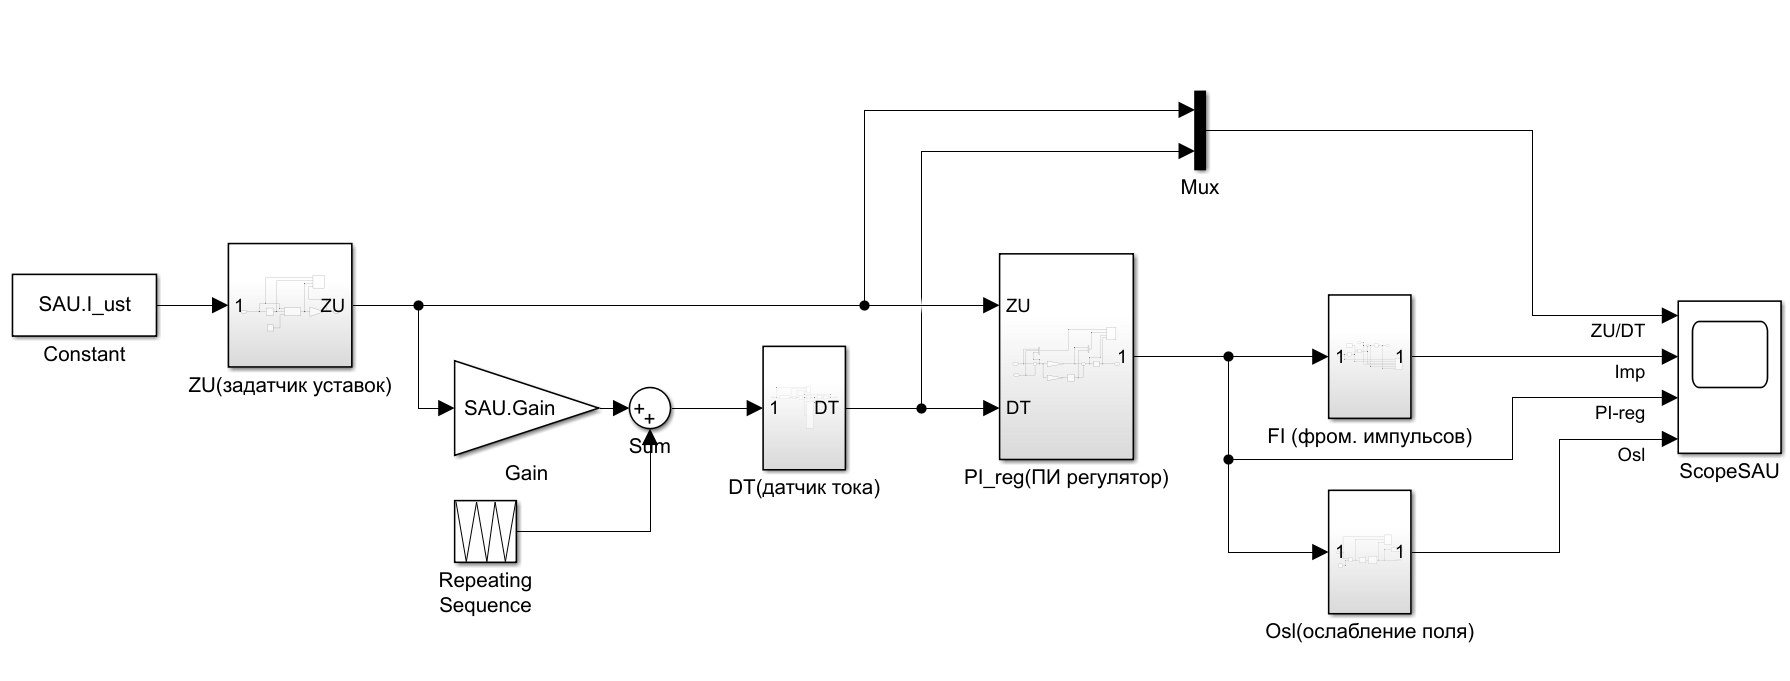

Рисунок 12. Компьютерная модель тестирования блоков САУ в Simulink

При снятии осциллограмм сигналов на вход блоков САУ подаем:

На вход блока задатчика уставок:

- Ток двиателя в расчетном режиме Iуст, А.:

В окне параметров блока "Constant" вводим значение тока Iуст:

SAU.I_ust = I_ust;

На вход блока датчика тока:

- Отношение единицы на коэффициент усиления задатчика уставок с масштабным множителем:

В окне параметров блока "Gain" вводим отношение единицы, деленной на значение коэффициента усиления задатчика уставок с масштабным множителем:

SAU.Gain = 1/ZU.K_Gain;

- Задающий сигнал в виде треугольного напряжения блока "Repeating Sequence":

Параметры блока "Repeating Sequence":

В окне параметров блока задаем необходимые значения в виде массива данных:

SAU.RepSec.Time = [0 1 2]; % период треугольного напряжения
SAU.RepSec.Output = [200 -200 200]; % амплитуда треугольного напряжения

Выходные сигналы блоков САУ:

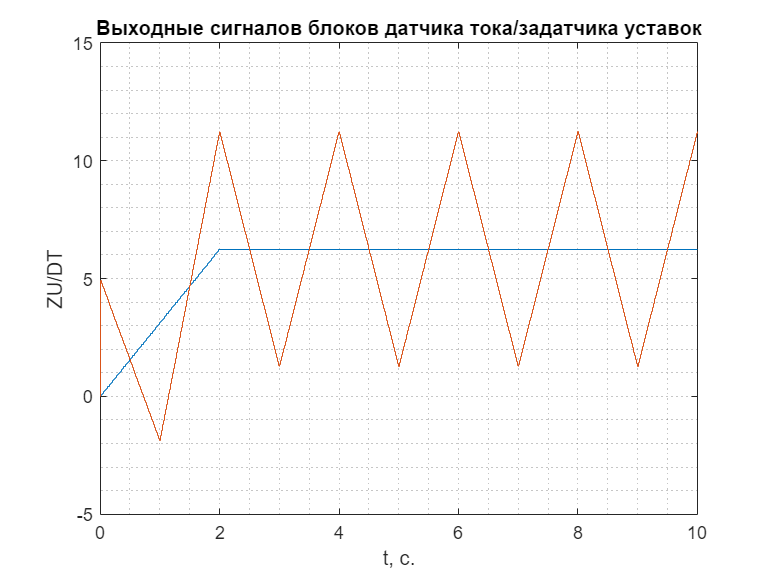

sim ('Block_SAU.slx');
plot(ans.ScopeSAU{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('ZU/DT');
    title('Выходные сигналов блоков датчика тока/задатчика уставок');
    ylim([-5 15]);

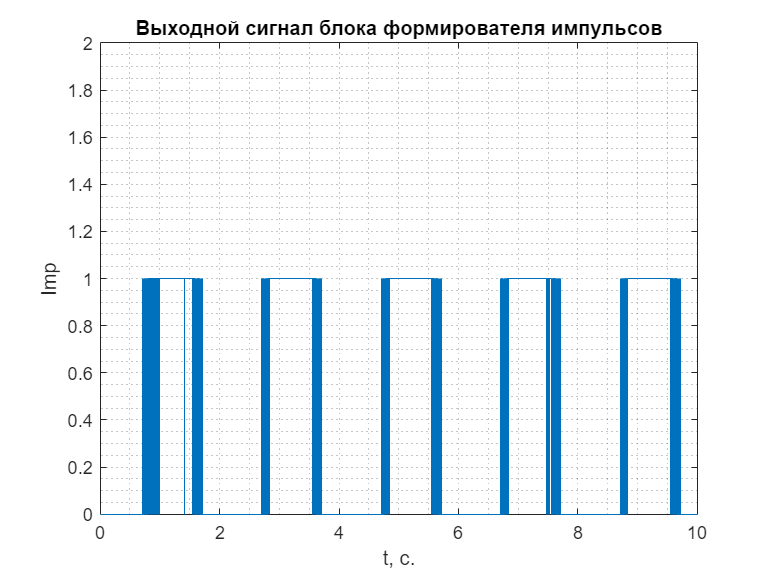

plot(ans.ScopeSAU{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Imp');
    title('Выходной сигнал блока формирователя импульсов'); 
    ylim([0 2]);

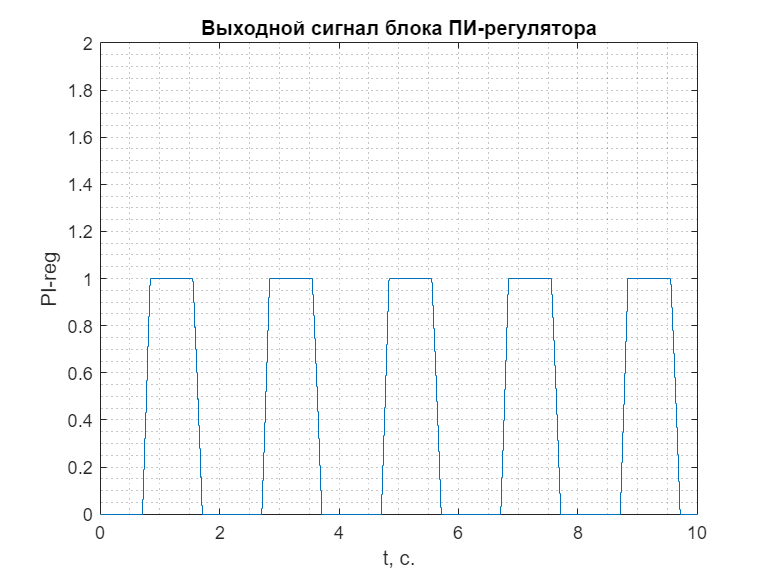

plot(ans.ScopeSAU{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Выходной сигнал блока ПИ-регулятора');
    ylim([0 2]);

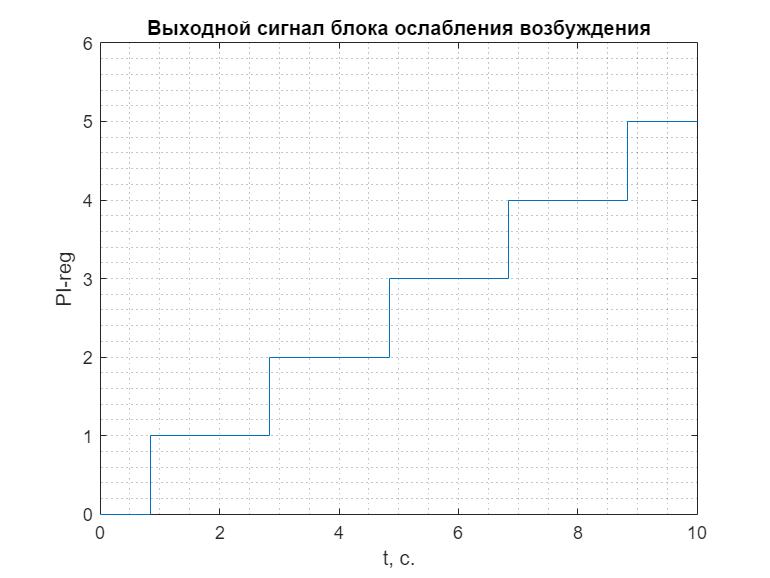

plot(ans.ScopeSAU{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Выходной сигнал блока ослабления возбуждения');
    ylim([0 6]);

Выходные сигналы блоков САУ в увеличенном масштабе:

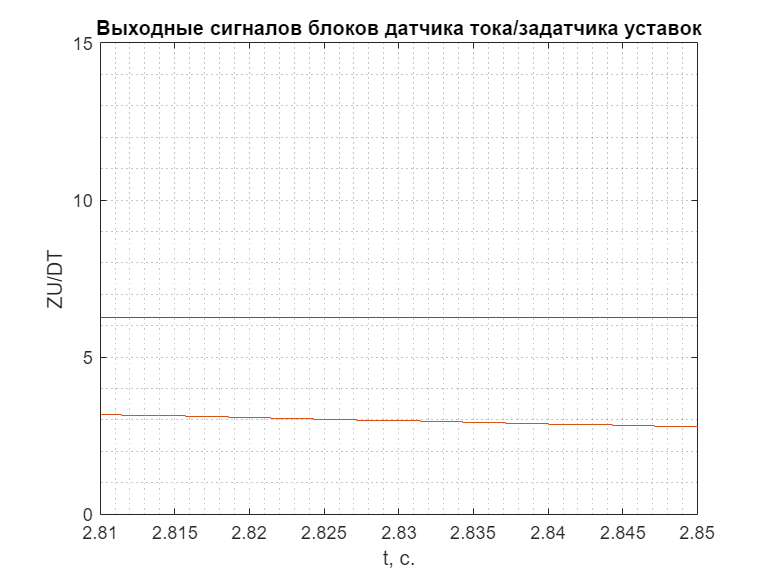

plot(ans.ScopeSAU{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('ZU/DT');
    title('Выходные сигналов блоков датчика тока/задатчика уставок');
    xlim([2.81 2.85]);
     ylim([0 15]);

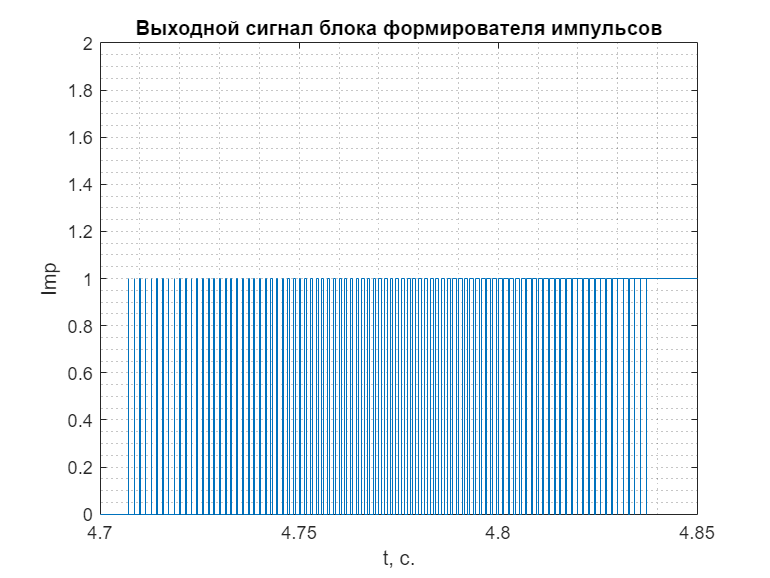

plot(ans.ScopeSAU{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Imp');
    title('Выходной сигнал блока формирователя импульсов');
    xlim([4.7 4.85]);
    ylim([0 2]);

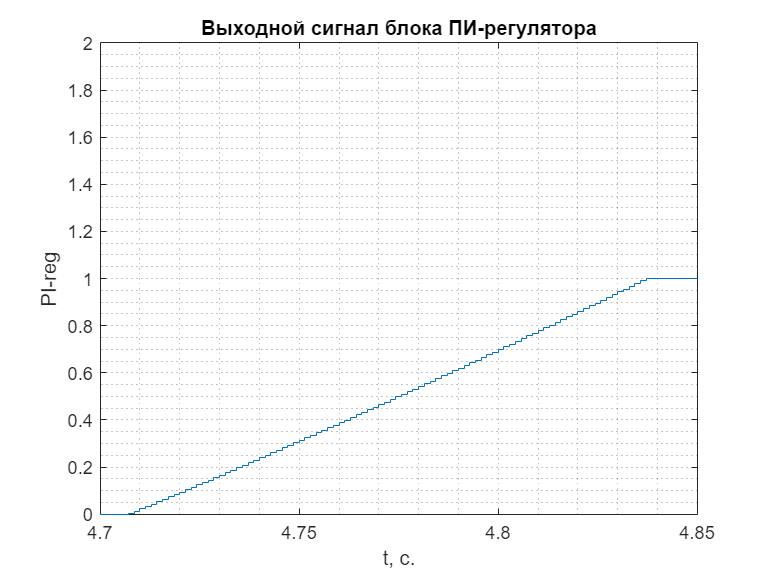

plot(ans.ScopeSAU{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Выходной сигнал блока ПИ-регулятора');
    xlim([4.7 4.85]);
    ylim([0 2]);

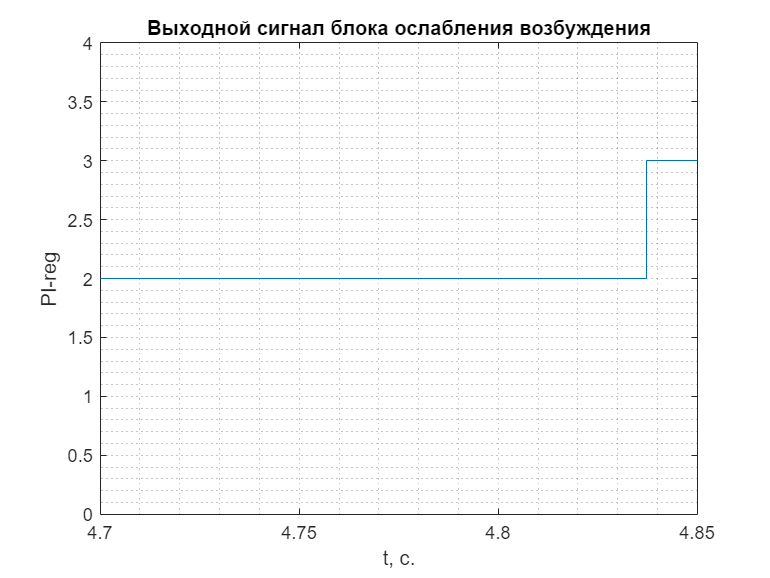

plot(ans.ScopeSAU{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('PI-reg');
    title('Выходной сигнал блока ослабления возбуждения');
    xlim([4.7 4.85]);
    ylim([0 4]);

## **2. Разработка модели электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения:**

**Программа работы:**

1) Сборка модели электропривода ЭПС с замкнутой САУ с использованием ранее разработанной схемы типового задания №3 и модели САУ.

2) Получение диаграмм режимов пуска и ослабления возбуждения ТЭД.

### **2.1. Построение компьютерной модели электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения:**

Компьютерная модель электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения в Simulink приведена на рисунке 13.

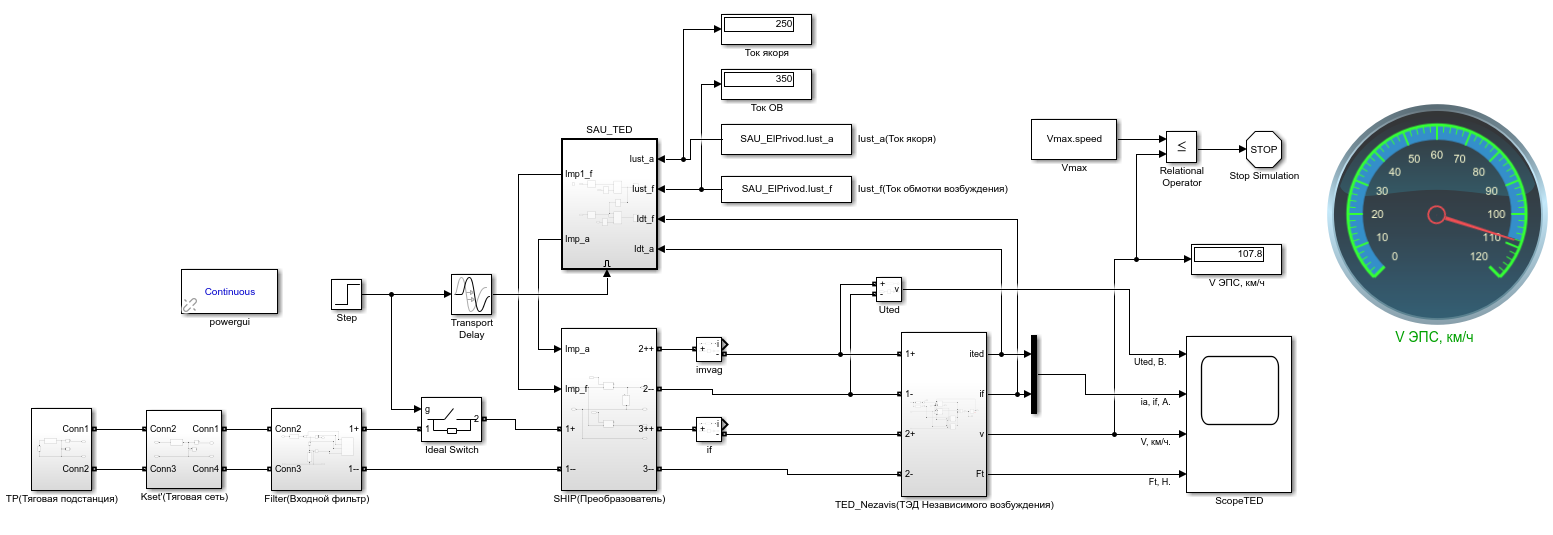

Рисунок 13. Компьютерная модель электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения в Simulink

Компьютерная модель САУ ТЭД независимого возбуждения  в Simulink приведена на рисунке 14.

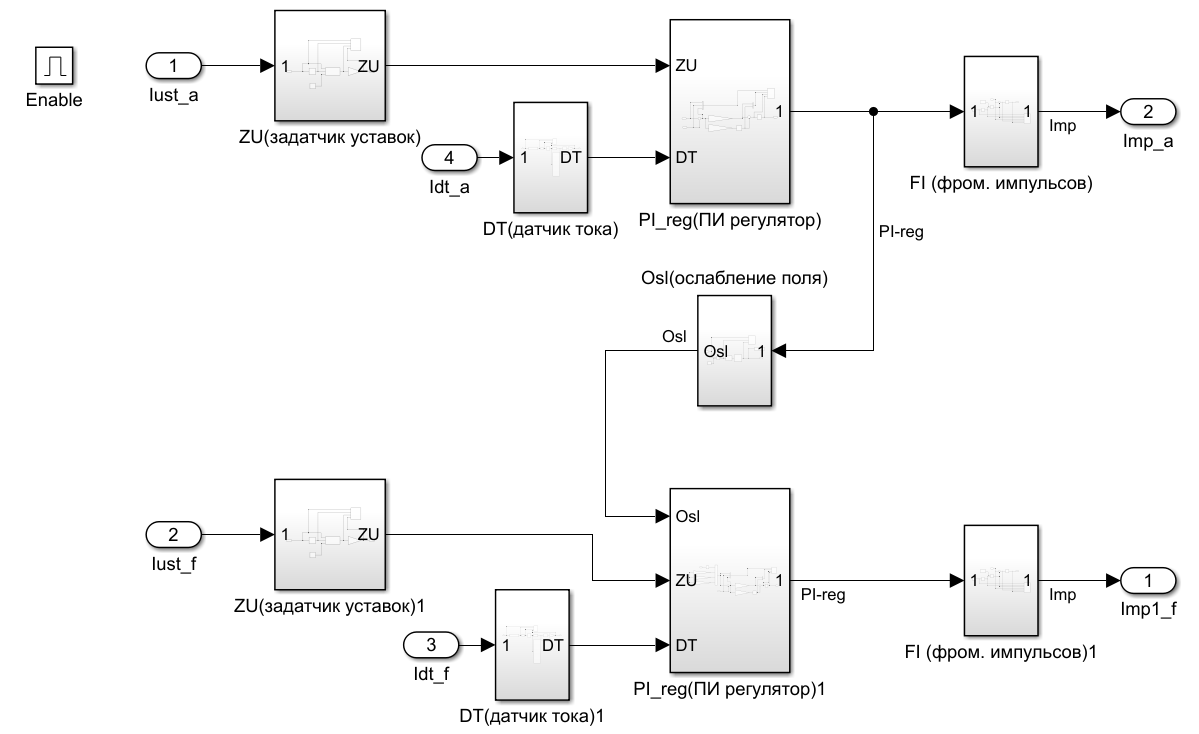

Рисунок 14. Компьютерная модель САУ ТЭД независимого возбуждения  в Simulink

#### **2.1.1. Ввод параметров в блоки модели системы автоматического управления САУ:**

Параметры ввода блока САУ подсистемы управления ослаблением поля:

В окне параметров блока "Counter" вводим максимальное количество подсчета единичных импульсов, приходящих на вход блока и значение начального подсчета единичных импульсов:

SAU_ElPrivod.Osl.Counter_MaxCount = 10;
SAU_ElPrivod.Osl.Counter_InitCount = 1;

Параметры ввода блока САУ подсистемы ПИ-регулятора управления током якоря:

В окне параметров блоков "Gain2" и "Gain1" задаем значения коэфициентов усиления пропорционального и интегрального каналов регулятора Kр и Kир соответсвенно (предварительно):

- коэфициент усиления пропорционального канала регулятора Kр принимаем равным 0,1:

SAU_ElPrivod.PI_reg.K_r = 0.1;    

- коэфициент усиления интегрального канала регулятора Kир принимаем равным 0.5:

SAU_ElPrivod.PI_reg.K_ir = 0.5; 

Параметры ввода блока САУ подсистемы ПИ-регулятора управления током возбуждения:

В окне параметров блоков "Gain", "Gain3" и "Gain4" вводим значения коэффициентов ступеней ослабления возбуждения ТЭД β0=1 β1=0,75 и  β2=0,5 соответственно:

SAU_ElPrivod.PI_reg1.Gain = 1;
SAU_ElPrivod.PI_reg1.Gain3 = 0.75;
SAU_ElPrivod.PI_reg1.Gain4 = 0.5;

В блоке насыщения "Saturation1" задаем ограничение входного сигнала ослабления поля на уровне от 3 до 1:

SAU_ElPrivod.PI_reg1.StUp_limit = 3;
SAU_ElPrivod.PI_reg1.StLow_limit = 1;

В окне параметров блоков "Gain2" и "Gain1" задаем значения коэфициентов усиления пропорционального и интегрального каналов регулятора Kр и Kир соответсвенно (предварительно):

- коэфициент усиления пропорционального канала регулятора Kр принимаем равным 0.05:

SAU_ElPrivod.PI_reg1.K_r = 0.05;    

- коэфициент усиления интегрального канала регулятора Kир принимаем равным 0.2:

SAU_ElPrivod.PI_reg1.K_ir = 0.2;  

#### **2.1.2. Ввод параметров в блоки модели электропривода ЭПС:**

Задание на вход САУ величины тока якоря и тока обмотки возбуждения ТЭД в расчетном режиме (Iуст, А.):

В окне параметров блоков "Iust_a" и "Iust_f" вводим значения величины тока якоря и тока обмотки возбуждения ТЭД в расчетном режиме (Iуст, А.):

- ток якоря ТЭД в расчетном режиме (ток уставки) Iя = Iуст, А.:

SAU_ElPrivod.Iust_a = 250;

- ток обмотки возбуждения ТЭД в расчетном режиме Iвозб. = Iмакс. (максимальный ток якоря), А.:

Imax.current = 350;
SAU_ElPrivod.Iust_f = Imax.current;

Задание на вход САУ значения времени шага:

В окне параметров блока Step вводим значение времени шага:

SAU_ElPrivod.Step_time = 2;

#### **2.1.3. Ввод рассчитанных ранее параметров в блоки модели электропривода ЭПС (типовое задание №3):**

#### **Параметры тяговой подстанции:**

Напряжение тяговой подстанции Uтп, В.:

TP.U_tp = 3450;

Активное сопротивление тяговой подстанции «Retp», Ом:

TP.R_etp = 0.0615;

Индуктивность тяговой подстанции «Letp», Гн:

TP.L_etp = 0.0025;

**Параметры тяговой сети:**

Активное сопротивление тяговой сети «Rekc», Ом:

TS.R_eks = 0.6885;

Индуктивность тяговой сети  «Lekc», Гн:

TS.L_eks = 0.0823;

**Параметры входного Г-образного фильтра:**

Активное сопротивление входного фильтра «Rf», Ом:

Filter.R_f = 0.001;

Емкость входного фильтра «Cf», Ф.:

Filter.C_f = 0.0036;

Индуктивность входного фильтра «Lf», Гн.:

Filter.L_f = 6.3136*(10^(-4));

**Параметры сглаживающих реакторов:**

Активное сопротивление сглаживающих реакторов «Rсгл», Ом:

TagPr.R_sgl = 0.001;

Индуктивнось сглаживающих реакторов «Lсгл», Гн:

TagPr.L_sgl = 0.0408;

**Параметры в блоках тяговых двигателей задаем согласно расчетов в типовом задании 1 (ТЗ1) и исходным данным:**

Параметры сопротивления и индуктивности обмотки якоря, Ом, Гн:

RaLa.Res =0.05;
RaLa.Ind = 0.0032;

Параметры сопротивления и индуктивности обмотки возбуждения, Ом, Гн:

ReLe.Res = 0.1;
ReLe.Ind = 0.0076;

Параметры характеристики намагничивания ТЭД:

CF.currentvozb = [0 25 50 100 150 175 200 250 300 350 400 450];
CF.CvF = [0 5 7.7 12.1 14.3 15 15.5 16.5 17.1 17.6 17.9 18.2];

Сопротивление шунтирующего резистора постоянного шунтирования ТЭД с коэффициентом β0=0,98 Ом.:

Rsh0.Res = 4.9;

Постоянная времени контура вихревых токов ТЭД Tвх, с:

Tokivx.time = 0.0230;

Коэффициент усиления дифференцирующего звена определяется числом витков полюсных катушек ТЭД, с(км/ч): 

Es.coefficient = 1.8471;

**Параметры уравнения движения поезда:**

Масса МВПС, т.:

UravDvij.M_mvps = 419.28;

Ускорение поступательного движения, м/с2:

UravDvij.dvdt = 2.0802*(10^(-6));

**Параметры широтно-импульсного преобразователя:**

Частота работы преобразователя, Гц:

source.f_c = 700;

Параметры IGBT транзистора:

Resistance Ron (Ohms):

IGBT.R_on = 0.0020; %Ом.

Forward voltage Vf (V) (Vce(on)):

deltaV_ce = 1; %В.
IGBT.V_f = deltaV_ce; %В.

Параметры силового диода (Diode):

Активное сопротивление силового диода rт, Ом:

Diode.r_t = 1.2*(10^-3);

Snubber resistance Rs (Ohms):

Diode.R_s = 5*10^6;

### **2.2. Диаграммы режимов пуска и ослабления возбуждения ТЭД независимого возбуждения электропривода ЭПС с замкнутой САУ (диаграммы пуска электропоезда):**

При достижении скорости v = vmax = 100 км/ч останавливаем моделирование и строим диаграммы пуска электропоезда.

Начальная и максимальная скорость движения электропоезда, км/ч.:

Vnach.speed = 120;
Vmax.speed = Vnach.speed*(0.9);

Запуск модели электропривода ЭПС с замкнутой САУ независимого возбуждения ТЭД (рисунок 13):

open('TZ4_SAU_ElPrivod');
sim('TZ4_SAU_ElPrivod');

Построение диаграмм режимов пуска и ослабления возбуждения ТЭД электропоезда:

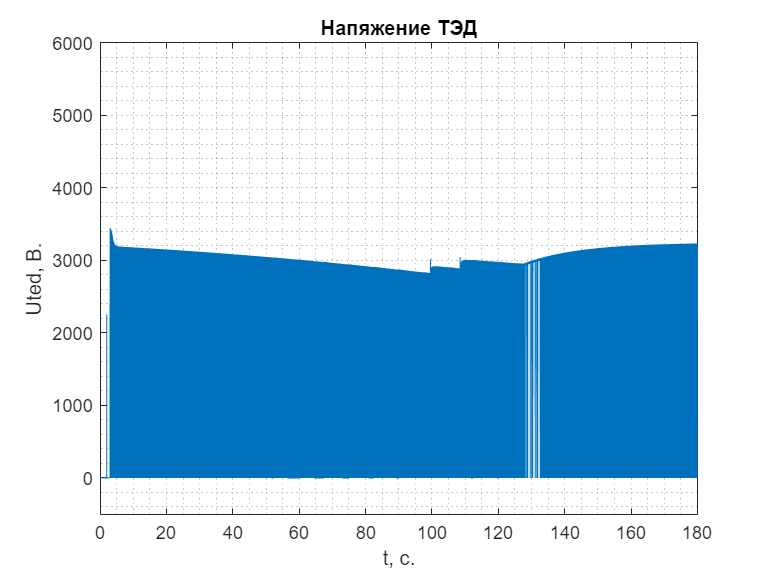

plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    ylim([-500 6000]);

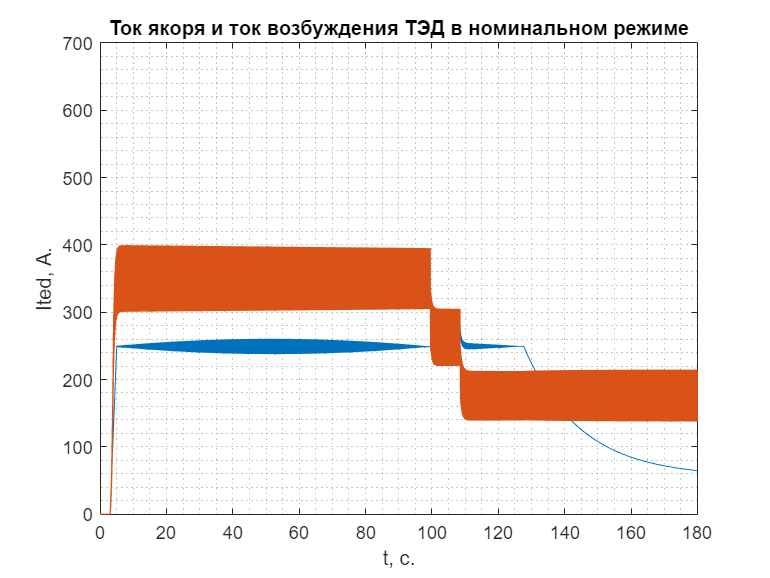

plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД в номинальном режиме');
    ylim([0 700]);

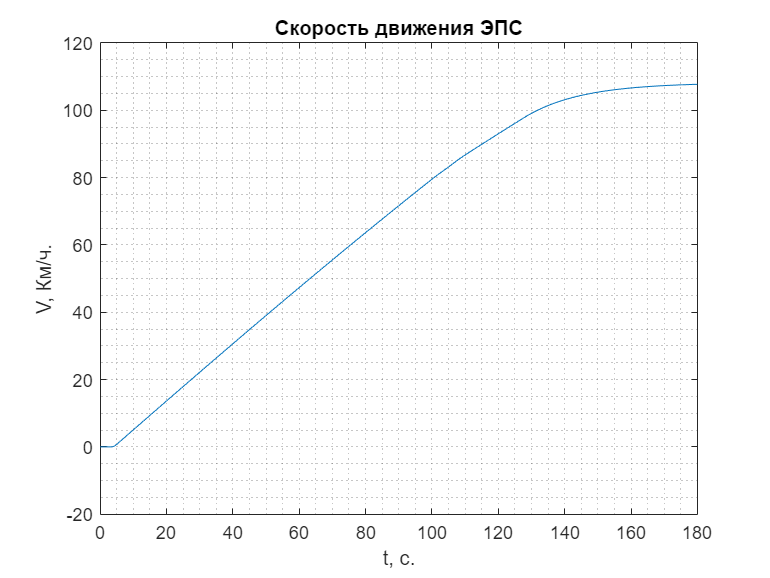

plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');

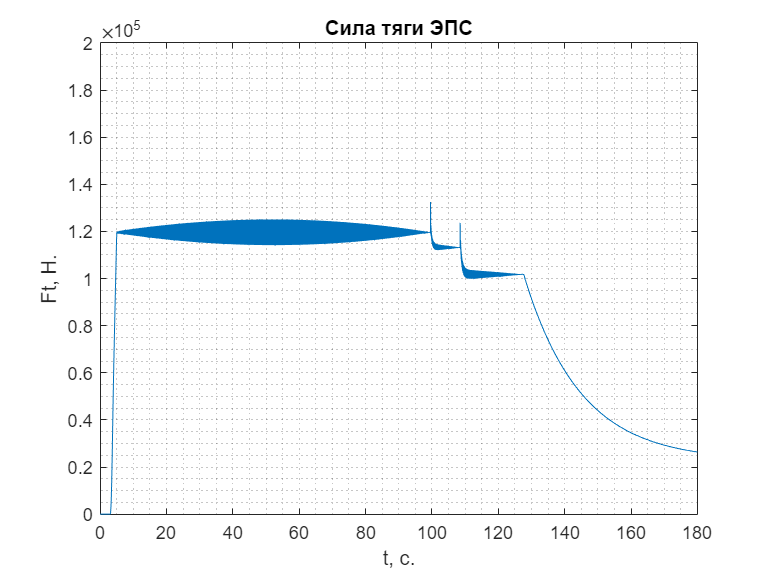

plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    ylim([0 200000]);

## **3. Настройка регуляторов САУ:**

**Программа работы:**

1) Настройка регулятора на компьютерной модели в соответствии с методическим пособием.

2) Получение диаграмм сигналов, необходимых для настройки регулятора.

### **3.1. Расчет параметров настройки регуляторов САУ на компьютерной модели методом Зиглера – Никольса:**

**Метод Зиглера – Никольса.**

Метод Зиглера - Никольса (Ziegler- Nichols). В работающей системе выключаются интегральная и дифференциальная составляющие регулятора (Тi = ∞,Td  =0), то есть система переводится в закон регулирования П. 

Путем последовательного увеличения Kкр с одновременной подачей небольшого скачкообразного сигнала задания добиваются возникновения в системе незатухающих колебаний, при Кр= Ккр, с периодом Tкр .При этом система находится на границе колебательной устойчивости (рисунок 15). Фиксируются значения  Kкр и Tкр. При появлении критических колебаний ни одна переменная системы не должна выходить на уровень ограничения.

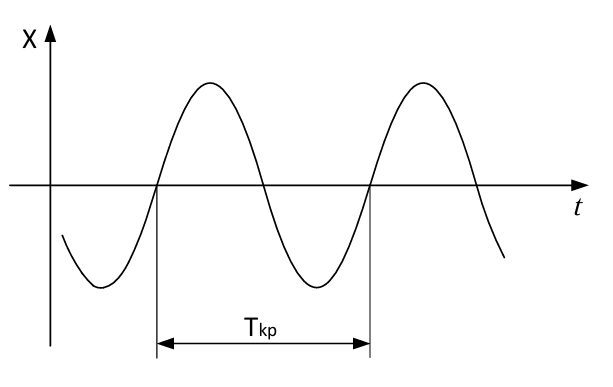

Рисунок 15.  График незатухающих колебаний, при Кр= Ккр, с периодом Tкр 

Перед началом настройки регулятора производим отключение системы управления полем ТЭД (рисунок 16):

По значениям T кр и Kкр рассчитываются параметры настройки регулятора:  

• P-регулятор: Kр = 0,55 Kкр ; 

• PI-регулятор: Kр = 0,45 Kкр ; Tир =Tкр /1,2; 

• PID-регулятор: Kр = 0,6 Kкр ; Tир =Tкр /2; Td=Tкр /8. 

Эта методика очень проста, но даёт не очень хорошие результаты. Тем не менее  она часто используется на практике. После расчёта параметров регулятора  обычно требуется его ручная подстройка для улучшения качества регулирования.

На рисунке 16 приведена компьютерная модель электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения для расчета параметров настройки регуляторов.

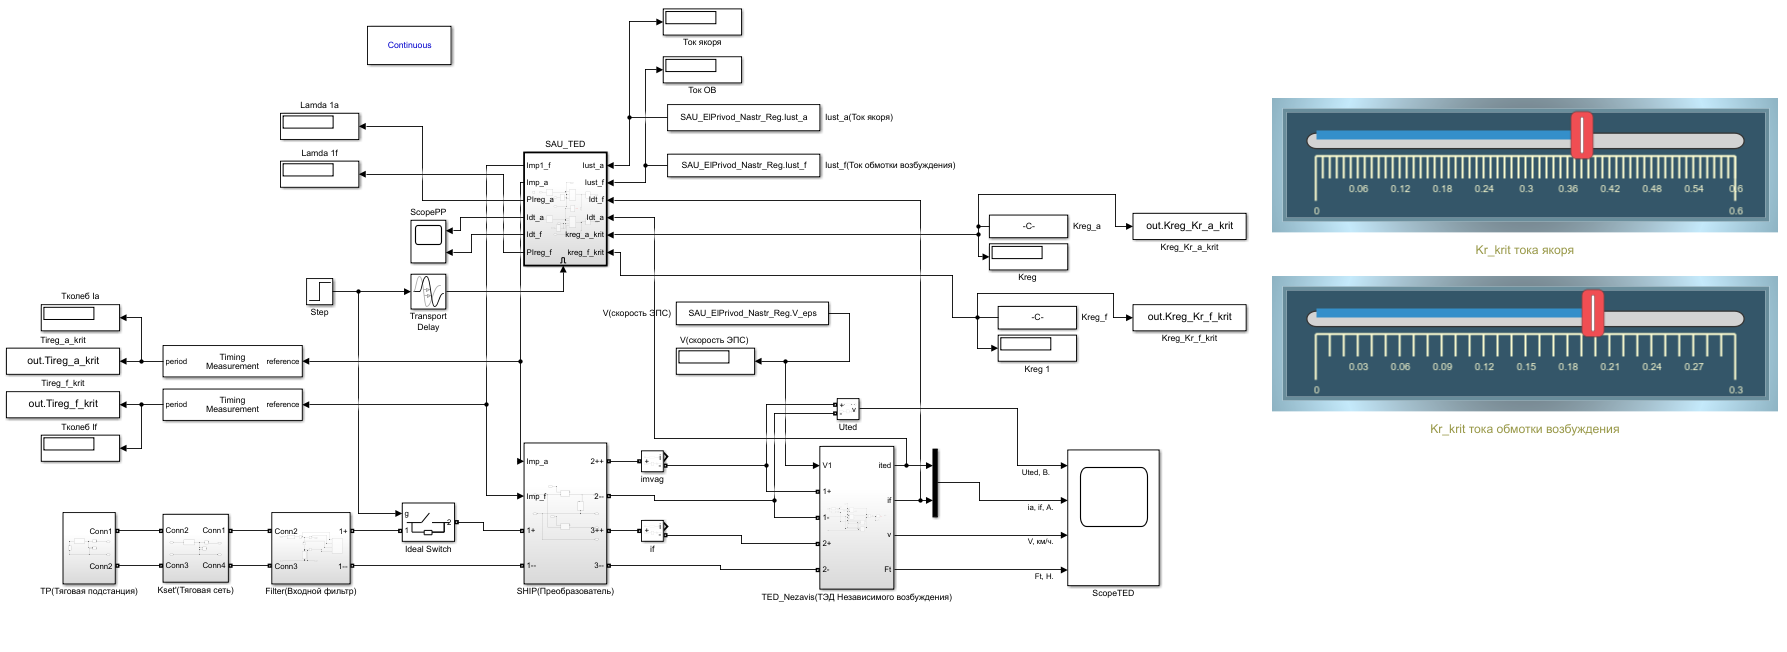

Рисунок 16. Компьютерная модель электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения для расчета параметров настройки регуляторов

Перед началом настройки регулятора отключаем систему управления полем ТЭД (рисунок 17):

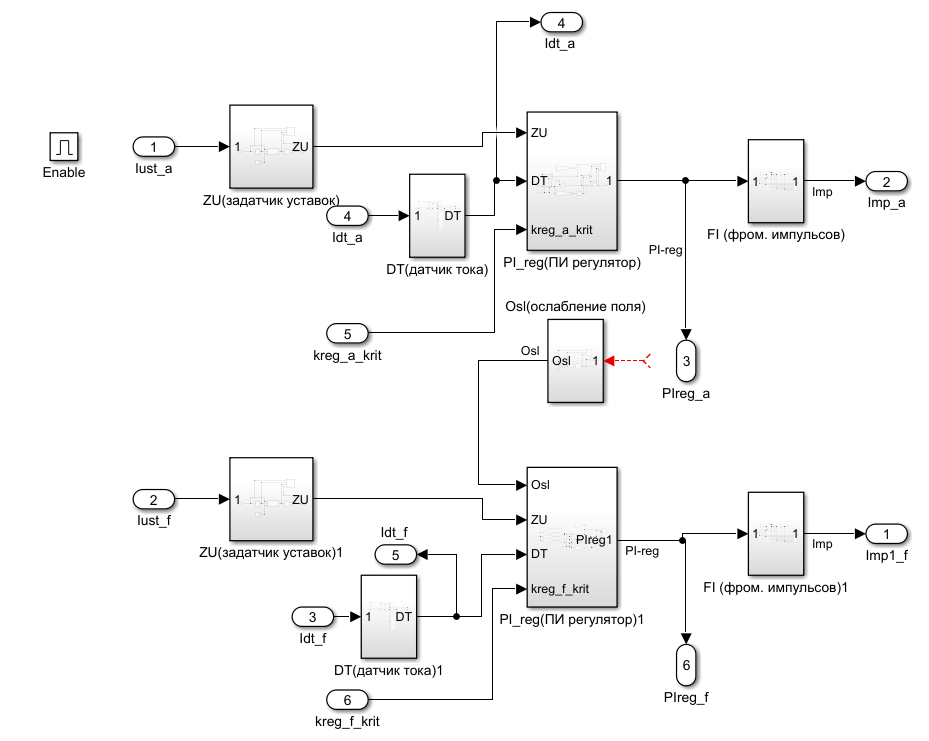

Рисунок 17. Отключение системы управления ослаблением поля ТЭД

Далее производим отключение интегрального канала регуляторов тока якоря и тока обмотки возбуждения ТЭД (рисунки 18-19):

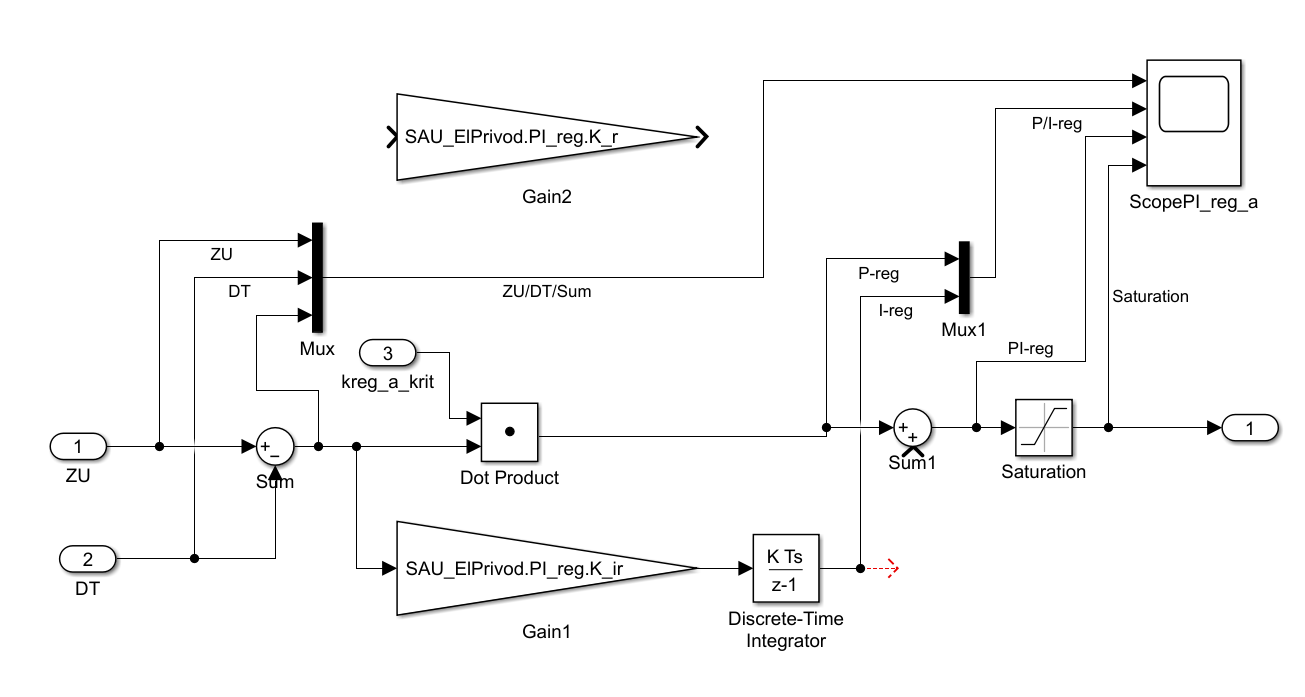

Рисунок 18. САУ с выключенным И-каналом регулятора тока якоря

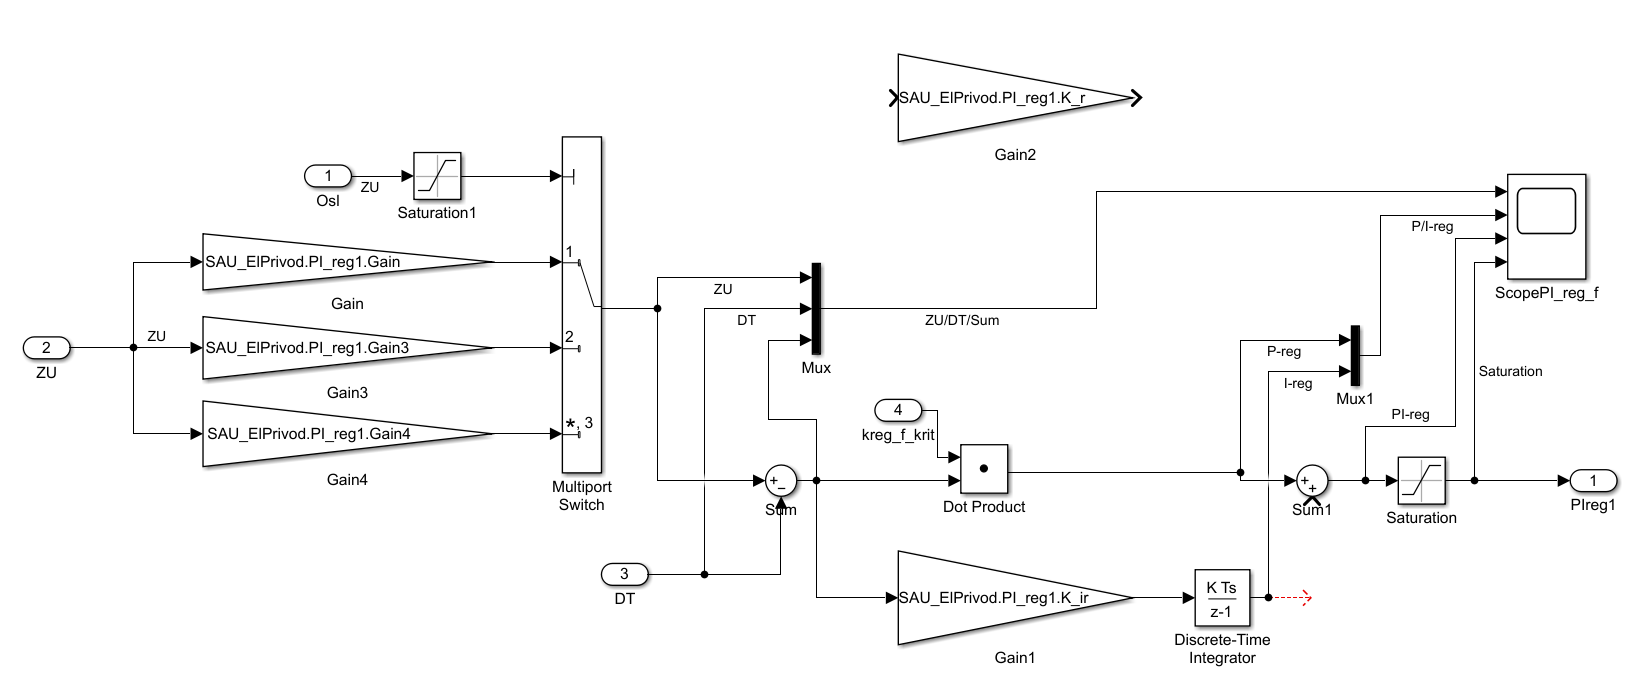

Рисунок 19. САУ с выключенным И-каналом регулятора тока обмотки возбуждения

#### **3.1.1. Ввод параметров в блоки модели системы автоматического управления САУ и модели электропривода ЭПС:**

Задаем на вход САУ величины тока якоря и тока обмотки возбуждения ТЭД в расчетном режиме (Iуст, А.):

В окне параметров блоков "Iust_a" и "Iust_f" вводим значения величины тока якоря и тока обмотки возбуждения ТЭД в расчетном режиме (Iуст, А.):

- ток якоря ТЭД в расчетном режиме (ток уставки) Iя = Iуст, А.:

SAU_ElPrivod_Nastr_Reg.Iust_a = 250;

- ток обмотки возбуждения ТЭД в расчетном режиме Iвозб. = Iмакс. (максимальный ток якоря), А.:

Imax.current = 350;
SAU_ElPrivod_Nastr_Reg.Iust_f = Imax.current;

Устанавливаем начальные значения коэффициентов усиления пропорционального Kр каналов ПИ-регуляторов так, чтобы ток ТЭД приходил к установившемуся значению:

Принимаем:

- первоначальный коэффициент регулирования для тока якоря (Кр=0,1):

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a = 0.1;

- первоначальный коэффициент регулирования для тока обмотки возбуждения (Кр=0,1):

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f = 0.1;

Устанавливаем скорость ЭПС так, чтобы коэффициент заполнения был равен 0,5 при достижении током ТЭД уставки, км/ч.:

Для этого запускаем вспомогательную модель управления скоростью ЭПС и с помощью ползунка настраиваем нужное значение скорости для коэффициента заполнения λ1 = 0.5:

%open('TZ4_SAU_ElPrivod_Nastr_Reg_Veps01');
sim('TZ4_SAU_ElPrivod_Nastr_Reg_Veps01');

Передаем данные о скорости движения на основною модель электропривода ЭПС с замкнутой САУ ТЭД независимого возбуждения:

TZ4_SAU_ElPrivod_Nastr_Reg_Veps01.V_eps = [];
TZ4_SAU_ElPrivod_Nastr_Reg_Veps01.V_eps(end+1) = max(ans.TZ43_Veps(end, 1));
SAU_ElPrivod_Nastr_Reg.V_eps = TZ4_SAU_ElPrivod_Nastr_Reg_Veps01.V_eps (1:end)

SAU_ElPrivod_Nastr_Reg = struct with fields:
       Iust_a: 250
       Iust_f: 350
    Kreg_Kr_a: 0.1000
    Kreg_Kr_f: 0.1000
        V_eps: 57.6500


Время моделирования:

Stop_time = 10; %с.

#### **3.1.2. Снятие осциллограмм моделирования переходных процессов с первоначальным коэффициентом регулирования:**

Запускаем процесс моделирования с первоначальным коэффициентом регулирования (Кр=0,1) и при коэффициенте заполнения равном 0,5:

%open('TZ4_SAU_ElPrivod_Nastr_Reg');
sim('TZ4_SAU_ElPrivod_Nastr_Reg');

Снимаем осциллограммы переходного процесса токов якоря и обмотки возбуждения при Кр_a = 0,1, Кр_f  = 0,01:

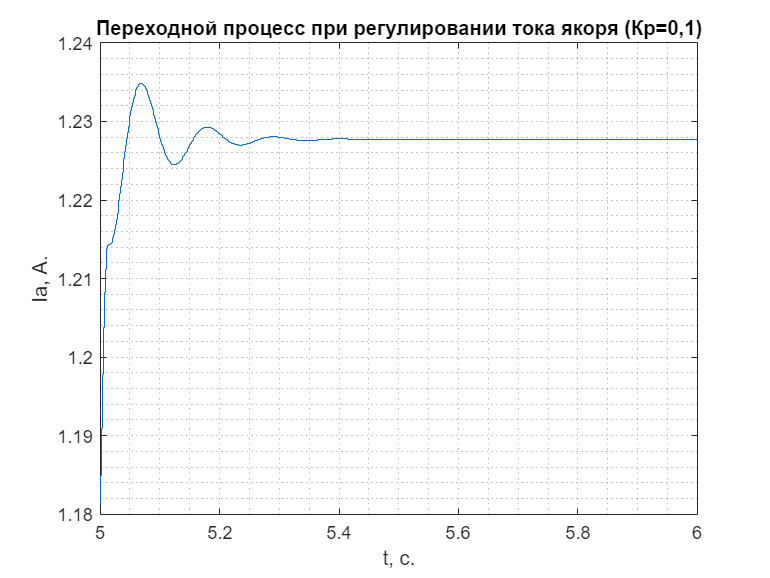

plot(ans.ScopePP{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ia, А.');
    title('Переходной процесс при регулировании тока якоря (Кр=0,1)');
    xlim([5 6]);

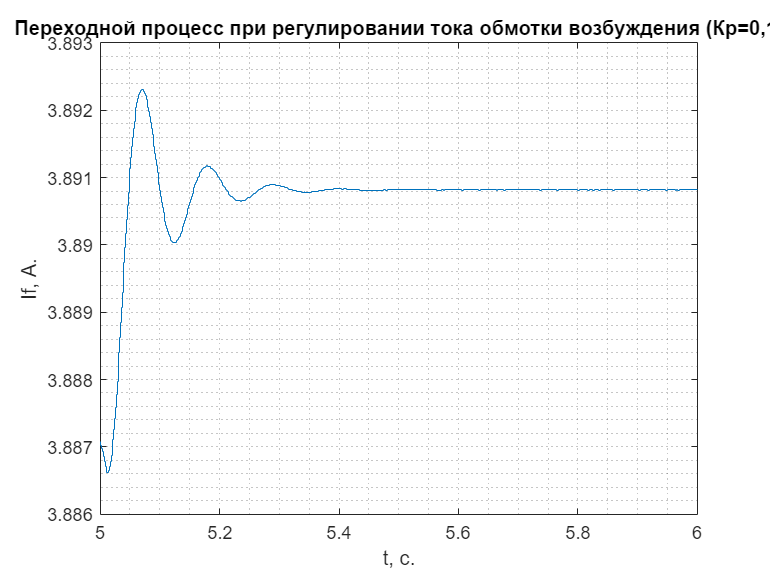

plot(ans.ScopePP{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('If, А.');
    title('Переходной процесс при регулировании тока обмотки возбуждения (Кр=0,1)');
     xlim([5 6]);

#### **3.1.3. Определение границ изменения коэффициентов усиления пропорционального канала регулятора Kр (получение незатухающих колебаний ПП):**

Далее с помощью ползунка в компьютерной модели изменяем коэффициент усиления регулятора в большую сторону так, чтобы добиться расходящегося процесса при регулировании тока ТЭД. Т.е. определяем границы изменения коэффициентов усиления пропорционального канала регулятора Kр для тока якоря и тока обмотки возбуждения:

%open('TZ4_SAU_ElPrivod_Nastr_Reg2');
sim('TZ4_SAU_ElPrivod_Nastr_Reg2');

Вариируем коэффициенты усиления в полученных границах диапазона так, чтобы получить значение, при котором процесс регулирования тока ТЭД будет колебательным устойчивым (т.е. производим увеличение коэффициента регулирования П-канала регулятора до получения незатухающих колебаний тока ТЭД:

Определяем величины коэффициентов регулирования П-канала регулятора при незатухающих колебаниях ПП:

- для регулирвания тока якоря:

Kreg_Kr_a_krit = [];
Kreg_Kr_a_krit = (ans.Kreg_Kr_a_krit(end, 1));
SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a_krit = Kreg_Kr_a_krit (end:1); %критическое значение

- для регулирвания тока обмотки возбуждения:

Kreg_Kr_f_krit = [];
Kreg_Kr_f_krit = (ans.Kreg_Kr_f_krit(end, 1));
SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f_krit = Kreg_Kr_f_krit (end:1); %критическое значение

Снимаем осциллограммы при незатухающих колебаниях токов якоря и обмотки возбуждения (графики) незатухающих колебаний, при Кр= Ккр, с периодом колебаний Tкр):

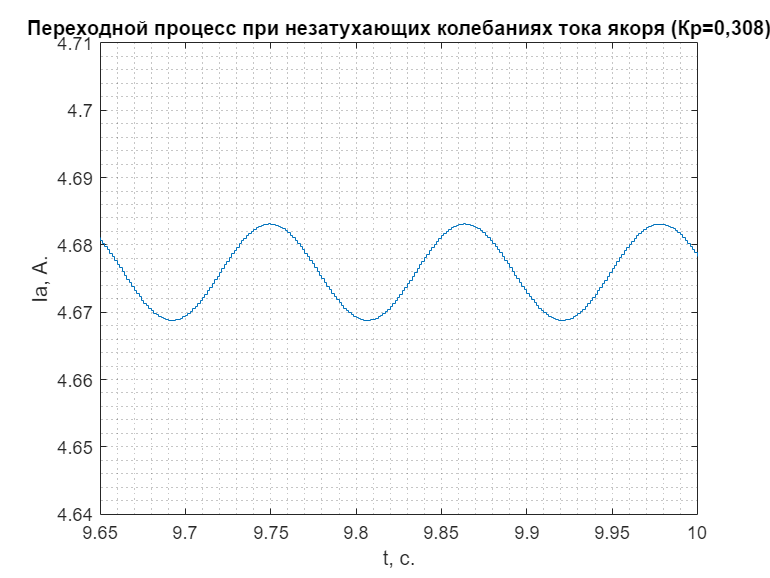

plot(ans.ScopePP{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ia, А.');
    title('Переходной процесс при незатухающих колебаниях тока якоря (Кр=0,308)');
    xlim([9.65 10]);
    ylim([4.64 4.71]);

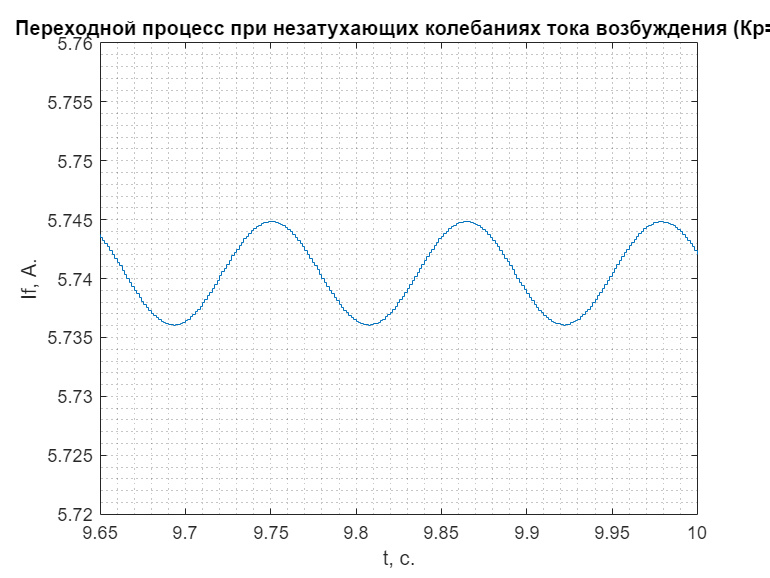

plot(ans.ScopePP{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('If, А.');
    title('Переходной процесс при незатухающих колебаниях тока возбуждения (Кр=)');
    xlim([9.65 10]);
    ylim([5.72 5.76]);

#### **3.1.4.  Рассчет параметров настройки регуляторов:**

Определяем период колебаний тока якоря и тока обмотки возбуждения ТЭД с помощью блоков "Timing Measurement":

Tireg_a_krit = [];
Tireg_f_krit = [];
Tireg_a_krit = max(ans.Tireg_a_krit(end, 1));
Tireg_f_krit = max(ans.Tireg_f_krit(end, 1));
SAU_ElPrivod_Nastr_Reg.Tireg_a_krit = Tireg_a_krit*80;
SAU_ElPrivod_Nastr_Reg.Tireg_f_krit = Tireg_f_krit*80;

По значениям постоянной времени интегратора Tкр и коэффициента усиления пропорционального Kкр канала ПИ-регулятора рассчитываем параметры настройки регуляторов:

для PI-регулятора: Kр = 0,45 Kкр ; Tир =Tкр /1,2;

Коэффициенты усиления пропорционального Kр канала ПИ-регулятора:

- для регулирвания тока якоря:

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a = 0.45* SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a_krit;

- для регулирвания тока обмотки возбуждения:

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f = 0.45* SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f_krit;

Отсюда постоянные времени интегратора Tир для обмотки якоря и обмотки возбуждения ТЭД:

- для регулирвания тока якоря:

SAU_ElPrivod_Nastr_Reg.Tireg_a = SAU_ElPrivod_Nastr_Reg.Tireg_a_krit/(1.2);

- для регулирвания тока обмотки возбуждения:

SAU_ElPrivod_Nastr_Reg.Tireg_f = SAU_ElPrivod_Nastr_Reg.Tireg_f_krit/(1.2);

Коэффициенты усиления интегрального Kир каналов ПИ-регулятора определяем по формуле, 1/А:

- для регулирвания тока якоря:

SAU_ElPrivod_Nastr_Reg.Kreg_Kir_a = SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a/SAU_ElPrivod_Nastr_Reg.Tireg_a;

- для регулирвания тока обмотки возбуждения:

SAU_ElPrivod_Nastr_Reg.Kreg_Kir_f = SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f/SAU_ElPrivod_Nastr_Reg.Tireg_f

SAU_ElPrivod_Nastr_Reg = struct with fields:
            Iust_a: 250
            Iust_f: 350
         Kreg_Kr_a: 0.1725
         Kreg_Kr_f: 0.0899
             V_eps: 57.6500
    Kreg_Kr_a_krit: 0.3834
    Kreg_Kr_f_krit: 0.1997
      Tireg_a_krit: 0.1143
      Tireg_f_krit: 0.1143
           Tireg_a: 0.0952
           Tireg_f: 0.0952
        Kreg_Kir_a: 1.8114
        Kreg_Kir_f: 0.9434


#### **3.1.5  Диаграммы пуска электропоезда с настроенными коэффициентами усиления регуляторов САУ:**

Полученные коэффициенты вводим в исходные модели блоков ПИ регуляторов, обратно подключая в цепь И-канал регулятора и выполняем моделирование переходных процессов:

Получаем диаграммы пуска электропоезда с настроенными коэффициентами усиления регуляторов:

При достижении скорости v = vmax = 100 км/ч останавливаем моделирование и строим диаграммы пуска электропоезда.

Начальная и максимальная скорость движения электропоезда, км/ч.:

Vnach.speed = 120;
Vmax.speed = Vnach.speed*(0.9);

Запуск модели электропривода ЭПС с базовыми коэффициентами усиления регуляторов:

open('TZ4_SAU_ElPrivod_Nastr_Reg3');
sim('TZ4_SAU_ElPrivod_Nastr_Reg3');

Построение диаграмм пуска электропоезда с базовыми коэффициентами усиления регуляторов (САУ с настройкой параметров по методу Зиглера – Никольса):

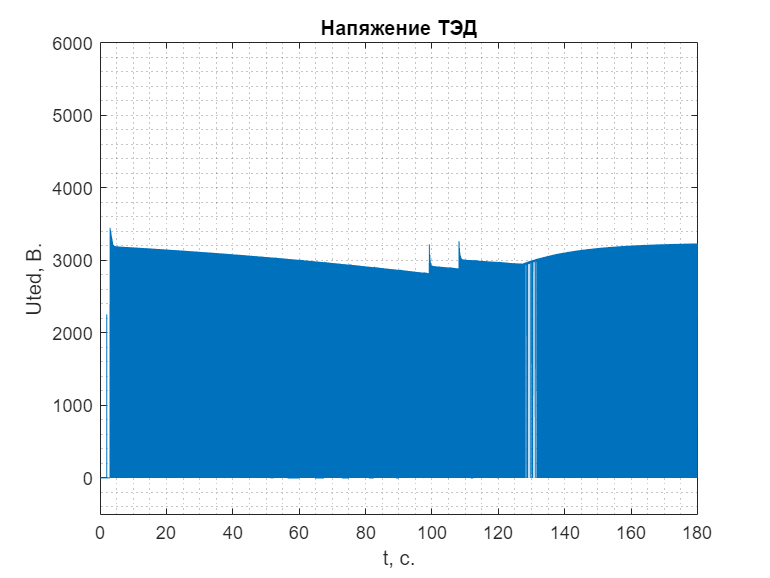

plot(ans.ScopeTED3{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    ylim([-500 6000]);

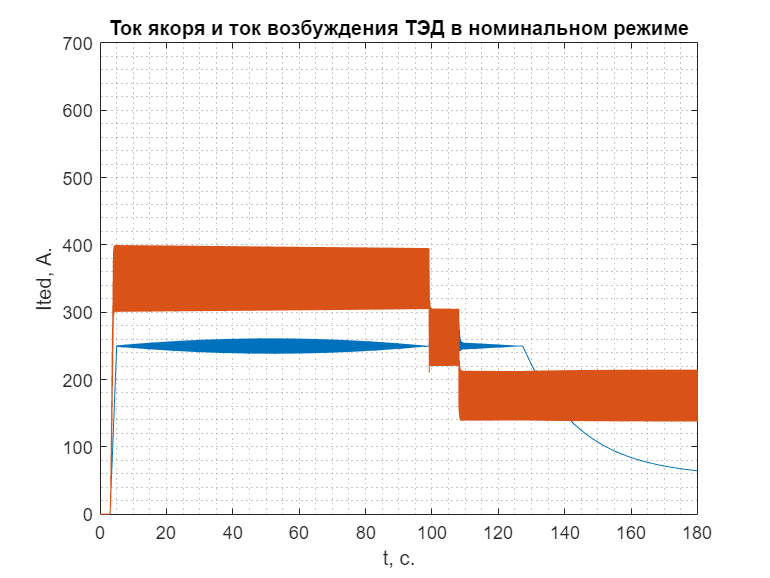

plot(ans.ScopeTED3{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД в номинальном режиме');
    ylim([0 700]);

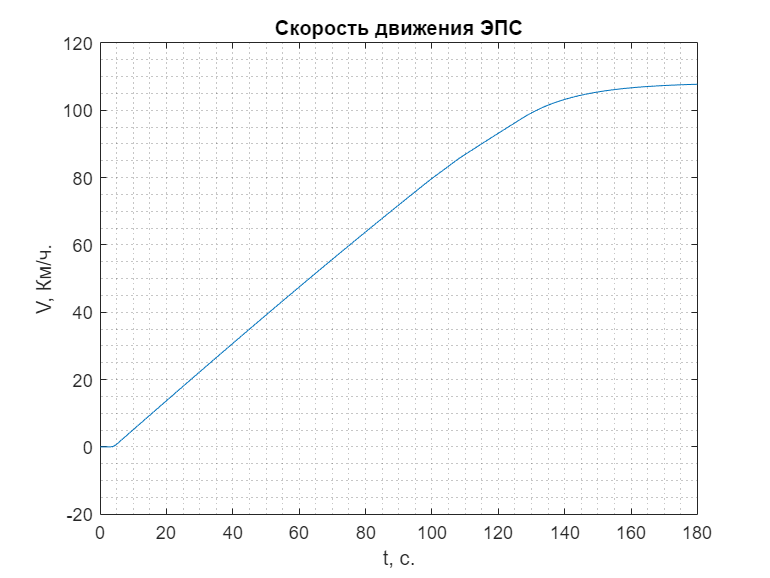

plot(ans.ScopeTED3{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');

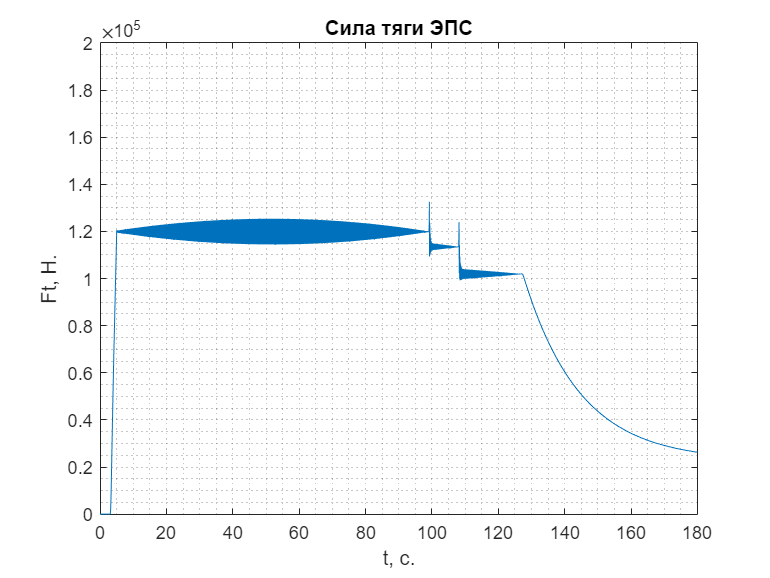

plot(ans.ScopeTED3{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    ylim([0 200000]);

### **3.2. Ручная подстройка параметров регуляторов:**

#### **3.2.1. Определение параметров регуляторов САУ при ручной поднастройке:**

После оценки результатов моделирования выполняем ручную подстройку параметров регуляторов:

Корректируем коэффициенты услиления, чтобы снизить колебания тока якоря и тока возбуждения:

Коэффициент усиления пропорционального Kр канала ПИ-регулятора тока якоря понижаем примерно на 25%:

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a = 0.45*SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a_krit*0.75;

Коэффициент усиления пропорционального Kр канала ПИ-регулятора тока обмотки возбуждения понижаем примерно на 30%:

SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f = 0.45*SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f_krit*0.7;

Тогда коэффициенты усиления интегрального Kир каналов ПИ-регулятора определяем как, 1/А:

SAU_ElPrivod_Nastr_Reg.Kreg_Kir_a = (SAU_ElPrivod_Nastr_Reg.Kreg_Kr_a*0.75)/SAU_ElPrivod_Nastr_Reg.Tireg_a;
SAU_ElPrivod_Nastr_Reg.Kreg_Kir_f = (SAU_ElPrivod_Nastr_Reg.Kreg_Kr_f*0.7)/SAU_ElPrivod_Nastr_Reg.Tireg_f

SAU_ElPrivod_Nastr_Reg = struct with fields:
            Iust_a: 250
            Iust_f: 350
         Kreg_Kr_a: 0.1294
         Kreg_Kr_f: 0.0629
             V_eps: 57.6500
    Kreg_Kr_a_krit: 0.3834
    Kreg_Kr_f_krit: 0.1997
      Tireg_a_krit: 0.1143
      Tireg_f_krit: 0.1143
           Tireg_a: 0.0952
           Tireg_f: 0.0952
        Kreg_Kir_a: 1.0189
        Kreg_Kir_f: 0.4623


Отсюда делаем вывод что амплитуда колебаний снизилась.

#### **3.2.2. Диаграммы пуска электропоезда при ручной подстройке параметров регуляторов:**

Проверяем настройку регуляторов:

Запуск модели электропривода ЭПС при ручной подстройке параметров регуляторов:

open('TZ4_SAU_ElPrivod_Nastr_Reg3');
sim('TZ4_SAU_ElPrivod_Nastr_Reg3');

Построение диаграмм пуска электропоезда при ручной подстройке параметров регуляторов: 

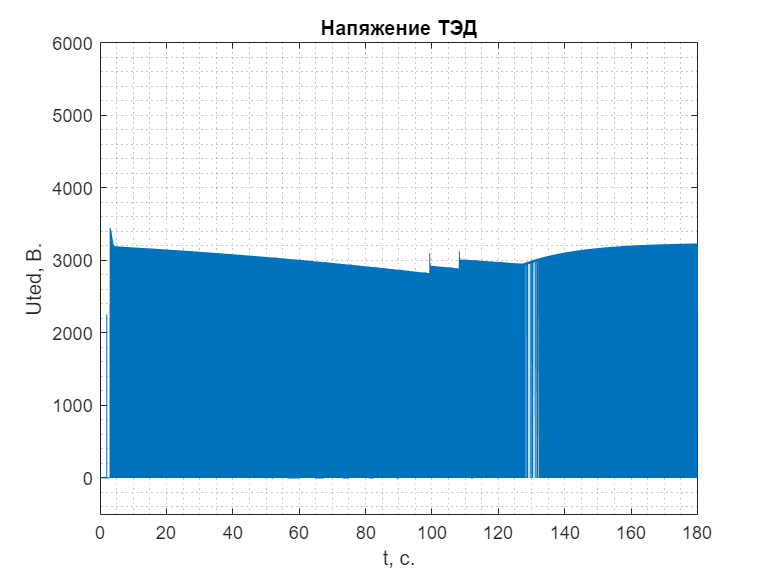

plot(ans.ScopeTED3{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    ylim([-500 6000]);

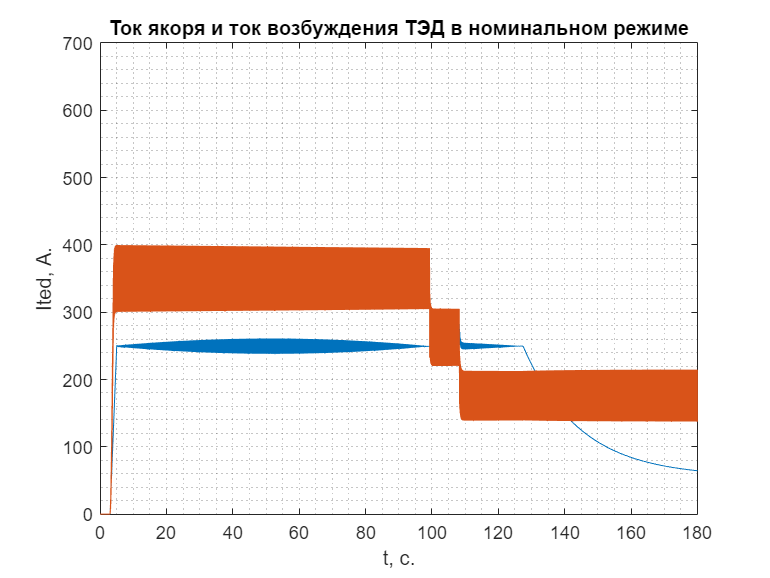

plot(ans.ScopeTED3{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД в номинальном режиме');
    ylim([0 700]);

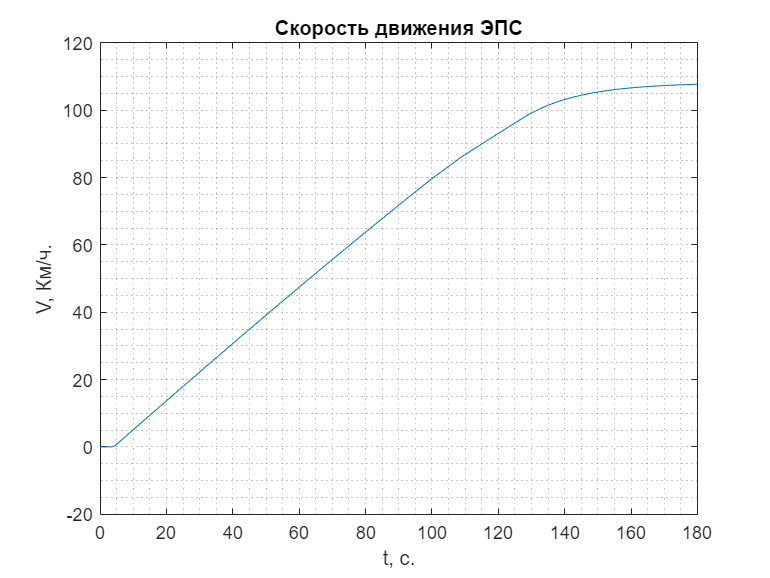

plot(ans.ScopeTED3{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');

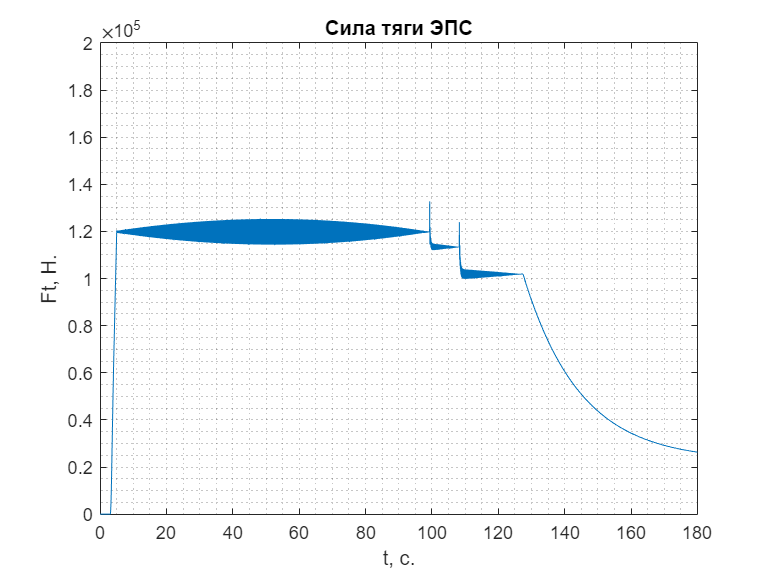

plot(ans.ScopeTED3{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    ylim([0 200000]);

## **Заключение**

В ходе выполнения типового задания №4 была произведена разработка системы автоматического управления электроприводом. Получены диаграммы тестовых сигналов с блоков САУ, а также диаграммы сигналов на выходе САУ.

Произведена разработка модели электропривода ЭПС с замкнутой САУ. В ходе выполнения моделирования получены диаграммы режимов пуска и ослабления возбуждения ТЭД, таких как напряжение на ТЭД, ток якоря и ток возбуждения ТЭД, а также скорость и сила тяги ЭПС.

Произведена настройка ПИ регуляторов САУ с помощью метода Зиглера – Никольса, а также ручная подстройка параметров регуляторов. На основании полученных в пункте 3 диаграмм режимов пуска и ослабления возбуждения ТЭД можно сдеать вывод, что система работает устойчиво, а значит регуляторы настроены правильно.